# Paint4Net: visualisation toolbox for COBRA

## Author(s):

Andrejs Kostromins, Biosystems Group, Department of Computer Systems, Latvia University of Agriculture, Liela iela 2, LV-3001 Jelgava, Latvia. 

Egils Stalidzans, Institute of Microbiology and Biotechnology, University of Latvia, Jelgavas iela 1, LV-1004, Latvia.

Modified for use in modern versions of MatLab by Rui Afonso Tavares, Līva Lukaša & Reinis Muižnieks, 2026.

## Reviewer(s): 

Agris Pentjuss, Institute of Microbiology and Biotechnology, University of Latvia, Jelgavas iela 1, LV-1004, Latvia.

Almut Heinken, Luxembourg Centre for Systems Biomedicine, Universiy of Luxembourg, 6 avenue du Swing, Belvaux, L-4367, Luxembourg.

## IMPORTANT NOTE

Paint4Net uses Bioinformatics Toolbox to generate visualisation layout, however it is not supported in .mlx causing an error during function execution. Thus the functions involving visualisation were run in regular MATLAB command window and each visualisation  layout was saved as a static figure and placed in the .mlx tutorial, while the corresponding functions were run in .mlx with visualisation feature turned off (input argument *drawMap *was set to 'false') to get outputs (without visualisation) in .mlx without crashing. Be aware of this issue when you are running the functions in .mlx. All *drawMap *input arguments are set to 'true' in .mlx. Change it to 'false' to avoid an error. 

## INTRODUCTION

A visual analysis of reconstructions and large stoichiometric models with elastic change of the visualization scope and representation methods becomes increasingly important due to the rapidly growing size and number of available reconstructions.

The Paint4Net is a COBRA Toolbox extension for automatic generation of a hypergraph layout of defined scope with the steady state rates of reaction fluxes of stoichiometric models. Directionalities and fluxes of reactions are constantly represented in the visualization while detailed information about reaction (ID, name and synonyms, and formula) and metabolite (ID, name and synonyms, and charged formula) appears placing the cursor on the item of interest. Additionally Paint4Net functionality can be used to: (1) get lists of involved metabolites and dead end metabolites of the visualized part of the network, (2) exclude (filter) particular metabolites from representation, (3) find isolated parts of a network and (4) find running cycles when all the substrates are cut down. Layout pictures can be saved in various formats and easily distributed. 

**Two functions with their arguments are used in the Paint4Net to define the scope of visualization: (1) [involvedMets, deadEnds] = draw by rxn(model, rxns, drawMap, direction, initialMet, excludeMets, flux) – to define scope by a list of reactions and (2) [directionRxns, involvedMets, deadEnds] = draw by met(model, metAbbr, drawMap, radius, direction, excludeMets, flux) – to define the metabolite of interest to see linked reactions within radius of, for instance, 2 reactions.** The function draw_by_rxn has 7 input arguments: (1) model – stands for stoichiometric reconstruction or model with constraints, (2) rxns – stands for a list of the reactions of interest for analysis, (3) drawMap (optional) – stands for request to generate visualization ('true' or 'false', default is 'false'), (4) direction (optional) – stands for algorithm visualization mode ('struc', 'sub', 'prod' or 'both') in order to visualize structure (struc) of reconstructions without FBA data or visualize substrates (sub), products (prod) or substrates and products (both) for models with flux constraints and FBA data (default is 'struc'), (5) initialMet (optional) – stands for metabolite of interest to be used by function draw by met (default is empty), (6) excludeMets (optional) – stands for a list of the excludable metabolites as a filter and (7) flux (optional) – stands for vector of FBA data of reactions flux distribution (default is vector of x characters if flux is not calculated). The last 5 arguments are optional and can be unset. The function draw_by_rxn has 2 outputs: (1) involvedMets – stands for a list of involved metabolites depending on the input arguments and (2) deadEnds – stands for a list of dead-end metabolites depending on the input arguments. The function draw_by_met has 7 input arguments: (1) model – stands for stoichiometric reconstruction or model with constraints, (2) metAbbr – stands for an input for metabolite of interest for analysis, (3) drawMap (optional) – stands for request to generate visualization ('true' or 'false', default is 'false'), (4) radius – stands for distance indicator between metabolite of interest and involved reactions (default is 1), (5) direction – stands for algorithm visualization mode ('struc', 'sub', 'prod' or 'both') in order to visualize structure (struc) of reconstructions without FBA data or visualize substrates (sub), products (prod) or substrates and products (both) for models with flux constraints and FBA data (default is 'struc'), (6) excludeMets (optional) – stands for a list of the excludable metabolites as a filter and (7) flux – stands for vector of FBA data of reactions flux distribution (default is vector of x characters for no flux). The last 5 arguments were optional in previous releases, and could be unset but are now required in the updated version. The function draw_by_met ha s 3 outputs: (1) directionRxns – stands for a list of involved reactions depending on the input arguments, (2) involvedMets – stands for a list of involved metabolites depending on the input arguments and (3) deadEnds – stands for alist of dead-end metabolites depending on the input arguments. 

The layout of the network is generated by using the digraph function built into MatLab. The visual representation of information in the layout (see Fig. 1) allows quick assessment of running processes generally.

### NOTE

Unlike in previous releases of Paint4Net, which relied on the now depreciated **Biograph** function and variables have been removed from MATLAB since the R2023b version, this version uses **digraph** instead, which while visually different, has similar functionality.

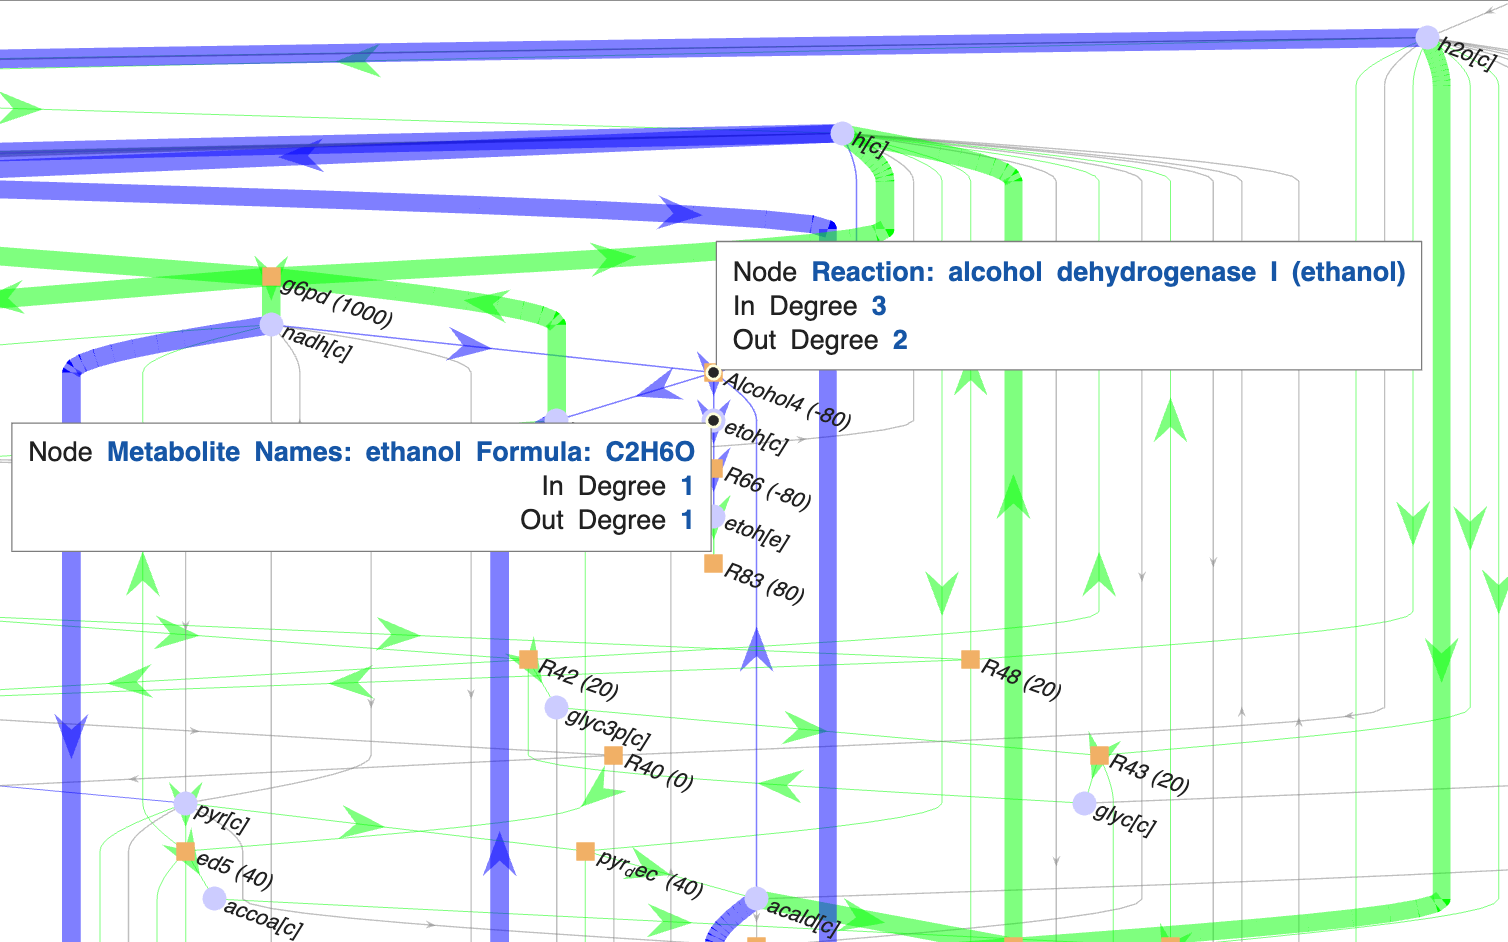

**Fig. 1 **Zoomed fragment of a large model. Reaction nodes (square) contain IDs and flux rates. Metabolite nodes (circle) are marked by IDs. Forward and reverse fluxes (arrows) are green and blue correspondingly, zero fluxes are grey. The thickness of an arrow is proportional to the rate of flux. Rectangles of blocked and exchange reactions are marked by red. Nodes can be chosen by a cursor to see detailed information: (1) Reaction name, number of nodes in and out and (2) ID, name, synonyms and charged formula for a metabolite.  Metabolite etoh*[c] *is selected by cursor for displaying of detailed information.  

Detailed information about any reaction and metabolite can be requested right on the visualization choosing the node of interest by cursor. To facilitate the analysis the Paint4Net creates a list of involved metabolites and a list of the dead end metabolites (metabolite cannot be produced or consumed caused by gap – missing reaction – in the model) (Thiele and Palsson, 2010) in the visualized part of the reaction network. That is a convenient feature analyzing larger visualizations where it becomes hard to be sure that a particular metabolite is or is not involved just by search of the abbreviation in the picture. The dead end metabolites are detected according to the S matrix (Palsson, 2006) of the biochemical model and the rates of reactions at steady state according to FBA. Flux rates below 10E−9 mmol g−1 h−1 are considered to be zero flux rates. To reduce the density of visualization a metabolite filter can be used. Stoichiometric model may have some particular metabolites (H, H2O, ATP, ADP, NAD, NADPH, NADP etc.), which are more involved in the metabolism, than other ones. It leads to a very tight interconnectivity and makes it harder to visualize larger models. For this reason both functions of the Paint4Net have special argument for the list of excludable metabolites. Each excluded metabolite reduces the number of interconnecting curves in the visualization of the model. Debugging of a model can be facilitated in several ways. The visualization shows the interconnections between reactions and metabolites and isolated parts of a network appear very clearly. There are three reasons why isolated reactions can be present in the model: (1) human made mistakes in the model while generating the model, (2) intentionally left gaps in case of no interest in specific metabolic process or (3) knowledge gaps in case of missing biochemical knowledge for the organism. Isolated parts can be related to metabolic dead-ends in the model (Thiele and Palsson, 2010). The Paint4Net is able to find the dead end metabolites and represent them in the visualization (red ellipses). Blocked reactions which cannot carry the fluxes (Thiele and Palsson, 2010) can appear in the model as intentionally blocked reactions (gene knockouts, flux constraints set to 0), however often there are cases when the model is stoichiometrically unbalanced or lower and upper bounds are set incorrectly. The Paint4Net can deal with this problem as well by showing the nodes of the blocked reactions in the visualization by red rectangles. The true power of visualization reflects when the user has to find Type III-extreme pathways (Thiele and Palsson, 2010) in the model. Those are stoichiometrically balanced cycles which can have fluxes even when all the substrate sources are cut down. According to FBA data the Paint4Net visualizes the network and then it is relatively easy to distinguish cycles by nonzero fluxes marked by green and blue arrows, which in most cases are caused by insufficient constraints of the flux and/or directionality. 

Paint4Net has been used in the development of stoichiometric models of Zymomonas mobilis (Pentjuss et al., 2013), Methanococcus maripaludis (Richards et al., 2016) and Kluyveromyces marxianus (Pentjuss et al., 2017). Paint4Net was used for to develop draft model, to identify network reactions connecting missing outputs to inputs and/or to produce figures for the published manuscript (Aurich and Thiele, 2012), (Demidenko et al., 2017), (Contador et al., 2015). It is used also for analysis and published figures in other studies (Koussa et al., 2014). Paint4Net is mentioned also as valuable supplement to other COBRA Tollboxes like ORCA (Mao and Verwoerd, 2014). Paint4Net has been used also for analysis of networks during building of modeling software (Rove et al., 2012) and supporting software tools (Rubina and Stalidzans, 2013), (Meitalovs and Stalidzans, 2013). Paint4Net is also used in a number of doctoral theses in different countries.

## MATERIALS

No materials are needed as Paint4Net is a software product.

## EQUIPMENT

The equipment has to be able to run MATLAB. 

## EQUIPMENT SETUP

The COBRA toolbox and the Bioinformatics toolbox are required to use the Paint4Net.

## PROCEDURE

The Paint4Net v1.4 contains two main commands for the visualization purposes:

- *[involvedMets, deadEnds] = draw_by_rxn(model, rxns, drawMap, direction, initialMet, excludeMets, flux)*;

- *[directionRxns, involvedMets, deadEnds] = draw_by_met(model,** metAbbr**, drawMap, radius, direction, excludeMets, flux)*.

## *Application of command* ***draw_by_rxn ***

***draw_by_rxn ***can be performed using **option** **A** in case COBRA model optimization results have to be visualized or **option** **B** if the interconnections between metabolites in COBRA file have to be visualized (See Fig. 2).

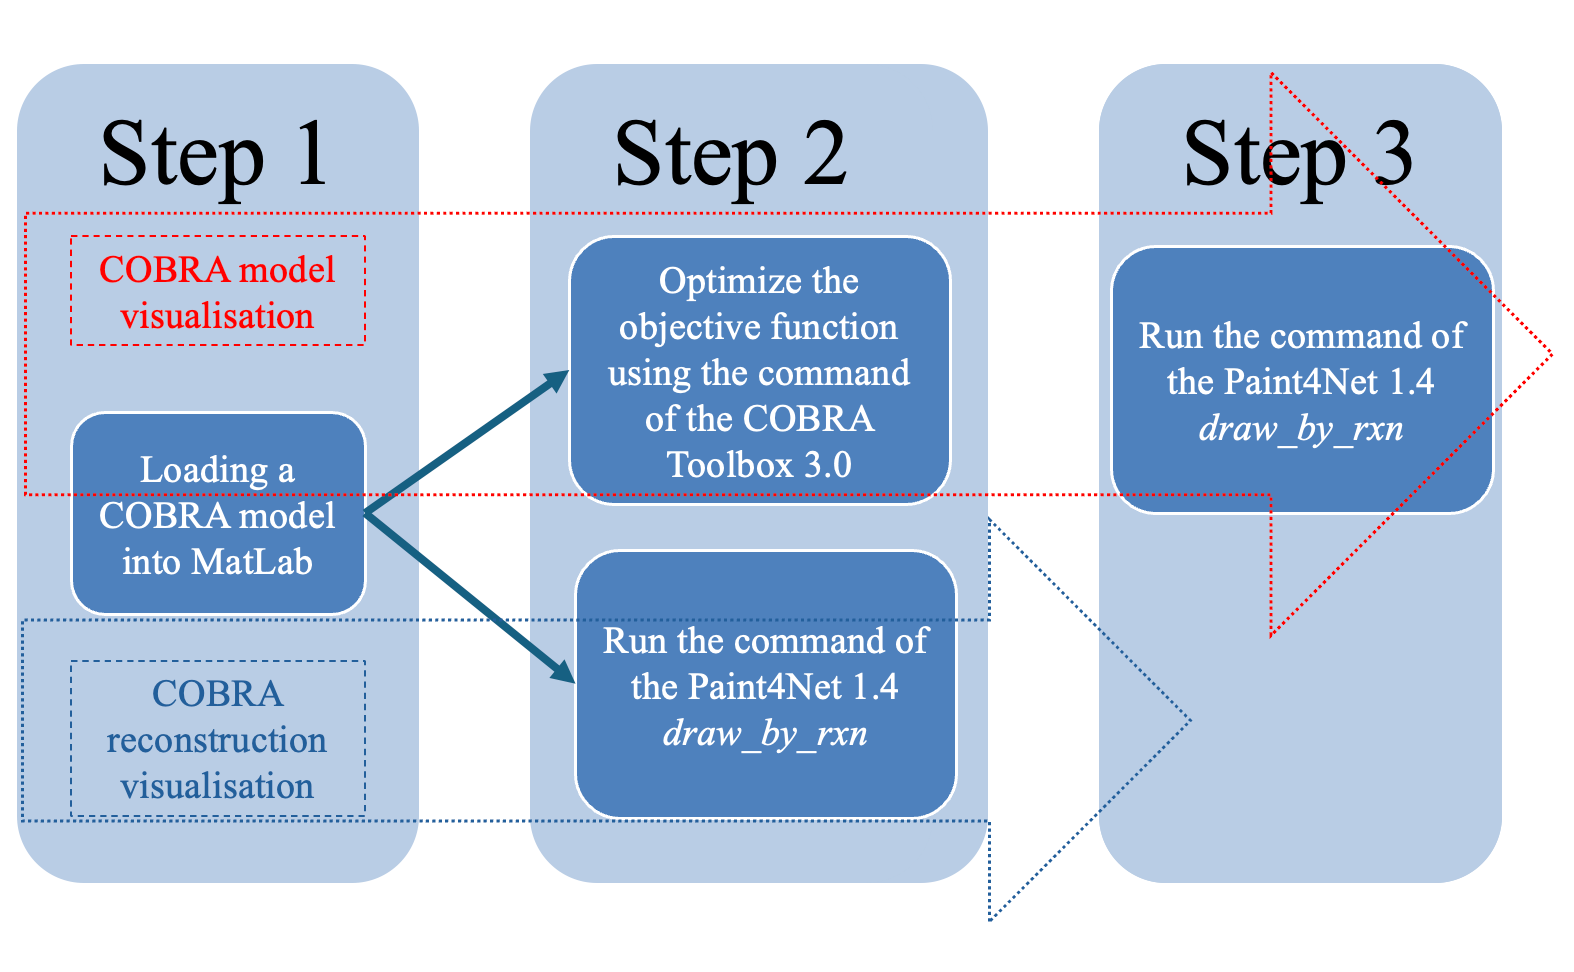

**Fig. 2.** The scenarios of an application of the command *draw_by_rxn*.

Before starting the tutorial, initialize the Cobra Toolbox if necessary and set a LP solver

initCobraToolbox(false) %don't update the toolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2026
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.50.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver ('gurobi', 'all', 1);


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > changeCobraSolver: Solver for MIQP problems has been set to gurobi.
 > changeCobraSolver: Solver gurobi not supported for problems of type CLP. No solver set for this problemtype 
 > changeCobraSolver: Solver gurobi not supported for problems of type EP. No solver set for this problemtype 
 > changeCobraSolver: Solver gurobi not supported for problems of type NLP. No solver set for this problemtype 


%changeCobraSolver ('glpk', 'all', 1);

## *A****.**** COBRA model visualization* 

**i.** a COBRA model has to be loaded into MATLAB. The sample model is available at [https://www.biosystems.lv/paint4net/sample_files](https://www.biosystems.lv/paint4net/sample_files). Download the file and extract it in a folder of your choice. You can also use your own model.

load("Paint4Net sample pack/Paint4Net_test_workspace.mat")

This will load a pre-run model and FBA Solution for the purposes of this tutorial. 

**ii.** optimization of the objective function by using the COBRA toolbox command *optimizeCbModel, *where the argument *model* corresponds to the COBRA model in the MATLAB workspace.

FBAsolution = optimizeCbModel(model)

FBAsolution = struct with fields:
    origStatText: []
               f: 80
              f0: NaN
              f1: 80
              f2: NaN
               v: [92×1 double]
               y: [78×1 double]
               w: [92×1 double]
               s: [78×1 double]
          solver: 'gurobi'
        lpmethod: ''
            stat: 1
        origStat: 'OPTIMAL'
            time: 0.0060
           basis: [1×1 struct]
          vars_v: []
               x: [92×1 double]
             obj: 80


This step ensures that a vector of the steady state fluxes *x* will be available for the command bio_draw_by_rxn.

FBAsolution.x

ans = 1.0e+03 *

         0
    0.0400
         0
    1.0000
   -0.9600
    0.0400
    0.0400
         0
         0
         0
         0
         0
    0.0400
         0
    0.0400


**iii.** execution of the command *[involvedMets, deadEnds] = bio_draw_by_rxn (model, rxns, drawMap, direction, initialMet, excludeMets, flux)*.

        Note: first time running may throw an error, which may be fixed by replacing {''} with "" or {""}, at which point any should work. 

Start_time = '2026_3_10_19_4_55.1841'

glyc12	f6p[c] 	->	g6p[c] 
glyc21	atp[c] + glc-D[c] 	->	g6p[c] + adp[c] + h[c] 
carb12	atp[c] + fru[c] 	<=>	f6p[c] + adp[c] + h[c] 
ed2	g6p[c] + nadp[c] 	<=>	h[c] + gl6p[c] + nadph[c] 
g6pd	g6p[c] + nad[c] 	<=>	h[c] + gl6p[c] + nadh[c] 
ed3	gl6p[c] + h2o[c] 	->	h[c] + pgl[c] 
ed1	pgl[c] 	<=>	h2o[c] + dgp[c] 
R035	nadp[c] + pgl[c] 	->	nadph[c] + co2[c] + ru5p-D[c] 
ppp4	xu5p-D[c] + e4p[c] 	<=>	f6p[c] + g3p[c] 
ppp3	xu5p-D[c] + r5p[c] 	<=>	g3p[c] + s7p[c] 
carb2	ru5p-D[c] 	<=>	xu5p-D[c] 
R040	ru5p-D[c] 	<=>	r5p[c] 
ppp5	dgp[c] 	<=>	g3p[c] + pyr[c] 
glyc3	g3p[c] 	<=>	dhap[c] 
glyc1	nad[c] + g3p[c] + pi[c] 	->	h[c] + nadh[c] + 13dpg[c] 
glyc4	atp[c] + 3pg[c] 	<=>	adp[c] + 13dpg[c] 
glyc7	2pg[c] 	<=>	3pg[c] 
glyc23	2pg[c] 	<=>	h2o[c] + pep[c] 
glyc14	atp[c] + pyr[c] 	<=>	adp[c] + h[c] + pep[c] 
pyr_dec	h[c] + pyr[c] 	->	co2[c] + acald[c] 
ed5	nad[c] + pyr[c] + coa[c] 	->	nadh[c] + co2[c] + accoa[c] 
Alcohol4	nad[c] + etoh[c] 	<=>	h[c] + nadh[c] + acald[c] 
acet_dehy	nad[c] + h2o[c] + acald[c

h =   GraphPlot with properties:

     NodeColor: [170×3 double]
    MarkerSize: 8
        Marker: {1×170 cell}
     EdgeColor: [289×3 double]
     LineWidth: [0.5000 7 0.2800 0.5000 0.2800 0.5000 7 0.5000 0.2800 0.2800 0.2800 7 6.7200 0.2800 0.5000 0.5600 7 0.5000 0.5000 0.5000 7 0.5000 0.5000 7 0.5000 0.5000 0.5000 0.5000 6.7200 0.2800 7 0.5000 0.5000 0.2800 0.5600 6.4400 … ] (1×289 double)
     LineStyle: '-'
     NodeLabel: {1×170 cell}
     EdgeLabel: {}
         XData: [56 36 87 120.5000 86.5000 72.5000 123.5000 61.5000 28 65.5000 33 45.5000 111 50 32 37.5000 54.5000 55.5000 54 53 52.5000 51 36 55 76.5000 54 87 87.5000 93.5000 44.5000 63 43 36 71.5000 5 27.5000 25 124.5000 118.5000 … ] (1×170 double)
         YData: [12 42 14 45 12 44 46 38 40 40 24 26 46 12 10 4 36 34 30 32 34 32 8 30 28 26 10 8 16 6 20 22 24 4 46 22 24 46 46 22 18 20 18 16 14 45 12 48 2 8 8 10 28 46 44 4 20 18 1

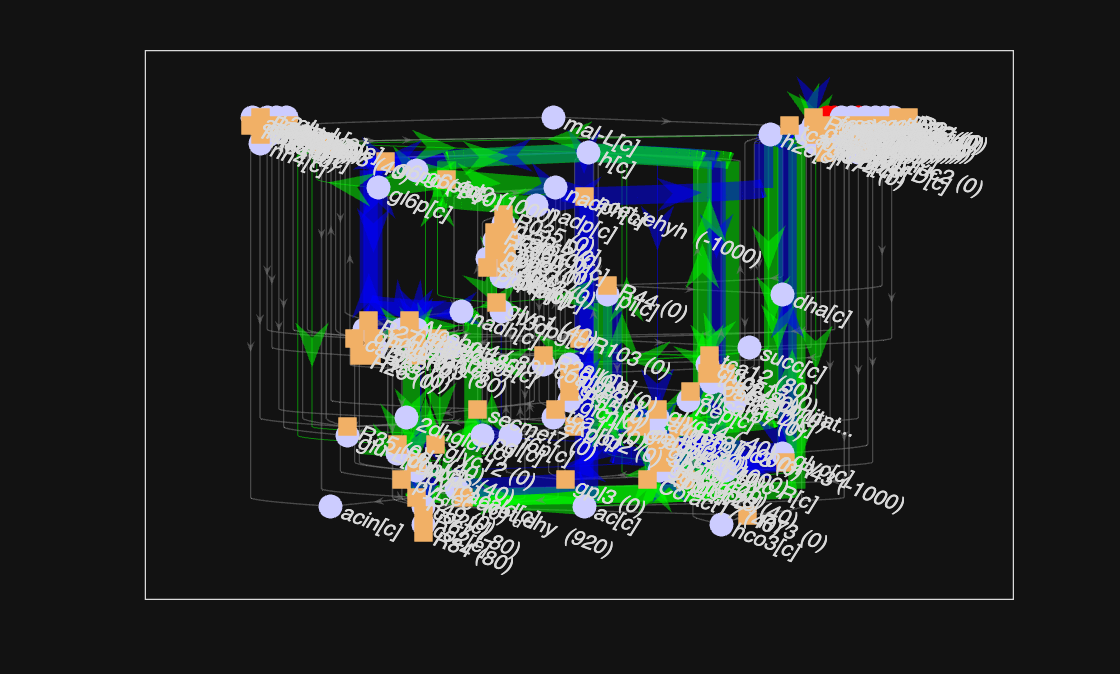

Involved_mets = 78×1 cell array
    {'f6p[c]'   }
    {'g6p[c]'   }
    {'atp[c]'   }
    {'glc-D[c]' }
    {'adp[c]'   }
    {'h[c]'     }
    {'fru[c]'   }
    {'nadp[c]'  }
    {'gl6p[c]'  }
    {'nadph[c]' }
    {'nad[c]'   }
    {'nadh[c]'  }
    {'h2o[c]'   }
    {'pgl[c]'   }
    {'dgp[c]'   }
    {'co2[c]'   }
    {'ru5p-D[c]'}
    {'xu5p-D[c]'}
    {'e4p[c]'   }
    {'g3p[c]'   }
    {'r5p[c]'   }
    {'s7p[c]'   }
    {'pyr[c]'   }
    {'dhap[c]'  }
    {'pi[c]'    }
    {'13dpg[c]' }
    {'3pg[c]'   }
    {'2pg[c]'   }
    {'pep[c]'   }
    {'acald[c]' }


Dead_ends = 3×1 cell array
    {'fru[e]'  }
    {'xyl-D[e]'}
    {'o2[e]'   }


[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, {''}, FBAsolution.x)

## *B.  COBRA reconstruction visualization* 

**i.** a COBRA model has to be loaded into MATLAB. 

load("Paint4Net sample pack/Paint4Net_test_workspace.mat")

**ii.** execution of the command *[involvedMets, deadEnds] = bio_draw_by_rxn (model, rxns, drawMap, direction, initialMet, excludeMets, flux) *which generates a reaction map without flux data. 

Start_time = '2026_3_10_19_4_55.9194'

glyc12	f6p[c] 	->	g6p[c] 
glyc21	atp[c] + glc-D[c] 	->	g6p[c] + adp[c] + h[c] 
carb12	atp[c] + fru[c] 	<=>	f6p[c] + adp[c] + h[c] 
ed2	g6p[c] + nadp[c] 	<=>	h[c] + gl6p[c] + nadph[c] 
g6pd	g6p[c] + nad[c] 	<=>	h[c] + gl6p[c] + nadh[c] 
ed3	gl6p[c] + h2o[c] 	->	h[c] + pgl[c] 
ed1	pgl[c] 	<=>	h2o[c] + dgp[c] 
R035	nadp[c] + pgl[c] 	->	nadph[c] + co2[c] + ru5p-D[c] 
ppp4	xu5p-D[c] + e4p[c] 	<=>	f6p[c] + g3p[c] 
ppp3	xu5p-D[c] + r5p[c] 	<=>	g3p[c] + s7p[c] 
carb2	ru5p-D[c] 	<=>	xu5p-D[c] 
R040	ru5p-D[c] 	<=>	r5p[c] 
ppp5	dgp[c] 	<=>	g3p[c] + pyr[c] 
glyc3	g3p[c] 	<=>	dhap[c] 
glyc1	nad[c] + g3p[c] + pi[c] 	->	h[c] + nadh[c] + 13dpg[c] 
glyc4	atp[c] + 3pg[c] 	<=>	adp[c] + 13dpg[c] 
glyc7	2pg[c] 	<=>	3pg[c] 
glyc23	2pg[c] 	<=>	h2o[c] + pep[c] 
glyc14	atp[c] + pyr[c] 	<=>	adp[c] + h[c] + pep[c] 
pyr_dec	h[c] + pyr[c] 	->	co2[c] + acald[c] 
ed5	nad[c] + pyr[c] + coa[c] 	->	nadh[c] + co2[c] + accoa[c] 
Alcohol4	nad[c] + etoh[c] 	<=>	h[c] + nadh[c] + acald[c] 
acet_dehy	nad[c] + h2o[c] + acald[c

h =   GraphPlot with properties:

     NodeColor: [170×3 double]
    MarkerSize: 8
        Marker: {1×170 cell}
     EdgeColor: [0.5000 0.5000 0.5000]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {1×170 cell}
     EdgeLabel: {}
         XData: [29.5000 11.5000 6.5000 109 48.5000 26.5000 105 41.5000 41 33.5000 65 70 84.5000 36.5000 28 67.5000 39 21 27 28.5000 39.5000 29.5000 71 37.5000 74.5000 71 97.5000 113.5000 69 100 63 65 138.5000 76.5000 136.5000 73.5000 … ] (1×170 double)
         YData: [9 35 40 37 7 33 38 17 25 19 27 29 21 23 21 3 15 13 9 11 13 11 13 9 7 5 17 40 5 31 9 11 38 7 38 15 17 38 38 15 7 9 7 5 3 37 1 40 1 17 19 19 7 38 36 11 13 11 9 7 40 39 37 40 40 40 40 40 40 39 40 40 40 40 40 40 40 40 8 36 … ] (1×170 double)
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0

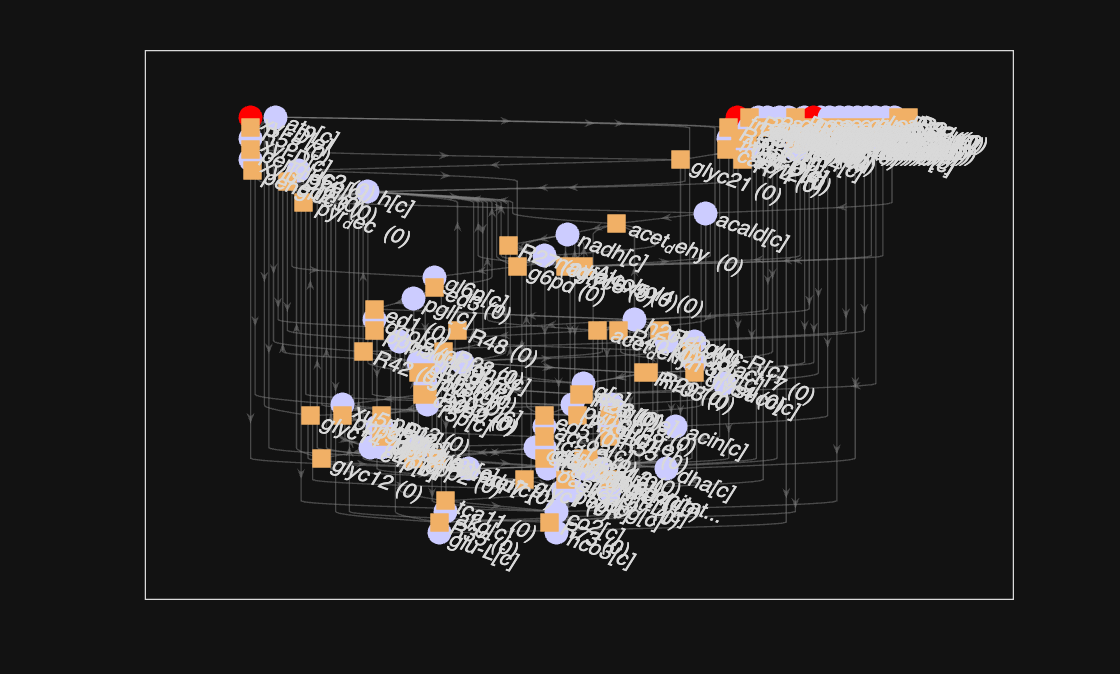

involvedMets = 78×1 cell array
    {'f6p[c]'   }
    {'g6p[c]'   }
    {'atp[c]'   }
    {'glc-D[c]' }
    {'adp[c]'   }
    {'h[c]'     }
    {'fru[c]'   }
    {'nadp[c]'  }
    {'gl6p[c]'  }
    {'nadph[c]' }
    {'nad[c]'   }
    {'nadh[c]'  }
    {'h2o[c]'   }
    {'pgl[c]'   }
    {'dgp[c]'   }
    {'co2[c]'   }
    {'ru5p-D[c]'}
    {'xu5p-D[c]'}
    {'e4p[c]'   }
    {'g3p[c]'   }
    {'r5p[c]'   }
    {'s7p[c]'   }
    {'pyr[c]'   }
    {'dhap[c]'  }
    {'pi[c]'    }
    {'13dpg[c]' }
    {'3pg[c]'   }
    {'2pg[c]'   }
    {'pep[c]'   }
    {'acald[c]' }


deadEnds = 3×1 cell array
    {'fru[e]'  }
    {'xyl-D[e]'}
    {'o2[e]'   }


[involvedMets, deadEnds] = draw_by_rxn(model, model.rxns, 'true')

x

In this case in the brackets at the square nodes are shown characters (0) indicating that fluxes at steady state were not calculated or applied to the map. This approach is useful in case of reconstruction visualization where fluxes are not calculated. The arrows in the end of the edges point on the forward directions of the reactions in the COBRA model.

## ***Input arguments of the command bio_draw_by_rxn***

The command bio_draw_by_rxn has several input arguments – *model, rxns*,* drawMap*, *direction*, *initialMet*, *excludeMets*, and* flux*. The last 5 arguments are optional; it means that the algorithm of the command bio_draw_by_rxn uses default values of those arguments, so user can ignore them if additional functionality is not actual.

**i. argument***** model***

This argument stands for a COBRA model in the MATLAB workspace.

**ii. argument***** rxns***

This argument represents a list of reactions from a COBRA model separated by a comma. The layout of map depends on this list, as a result if new abbreviation is added or some deleted in the list the layout will change as well. To prevent layout change by potential mistakes and save time by not creating the list every time from scratch it is possible to create a *cell *type vector in the MATLAB workspace that contains the static abbreviations of the reactions in the COBRA model and use it as argument *rxns*. 

rxns = {'glyc12', 'glyc21', 'carb12', 'ed2'}

rxns = 1×4 cell array
    {'glyc12'}    {'glyc21'}    {'carb12'}    {'ed2'}


[involvedMets, deadEnds] = draw_by_rxn(model, rxns)

Start_time = '2026_3_10_19_4_56.385'

involvedMets = 10×1 cell array
    {'f6p[c]'  }
    {'g6p[c]'  }
    {'atp[c]'  }
    {'glc-D[c]'}
    {'adp[c]'  }
    {'h[c]'    }
    {'fru[c]'  }
    {'nadp[c]' }
    {'gl6p[c]' }
    {'nadph[c]'}


deadEnds = 5×1 cell array
    {'glc-D[c]'}
    {'fru[c]'  }
    {'nadp[c]' }
    {'gl6p[c]' }
    {'nadph[c]'}


Another example is a list of reaction in the COBRA model which can be accessed by *model.rxns*. It illustrates all COBRA model.

[involvedMets, deadEnds] = draw_by_rxn(model, model.rxns)

Start_time = '2026_3_10_19_4_56.4125'

involvedMets = 78×1 cell array
    {'f6p[c]'   }
    {'g6p[c]'   }
    {'atp[c]'   }
    {'glc-D[c]' }
    {'adp[c]'   }
    {'h[c]'     }
    {'fru[c]'   }
    {'nadp[c]'  }
    {'gl6p[c]'  }
    {'nadph[c]' }
    {'nad[c]'   }
    {'nadh[c]'  }
    {'h2o[c]'   }
    {'pgl[c]'   }
    {'dgp[c]'   }
    {'co2[c]'   }
    {'ru5p-D[c]'}
    {'xu5p-D[c]'}
    {'e4p[c]'   }
    {'g3p[c]'   }
    {'r5p[c]'   }
    {'s7p[c]'   }
    {'pyr[c]'   }
    {'dhap[c]'  }
    {'pi[c]'    }
    {'13dpg[c]' }
    {'3pg[c]'   }
    {'2pg[c]'   }
    {'pep[c]'   }
    {'acald[c]' }


deadEnds = 3×1 cell array
    {'fru[e]'  }
    {'xyl-D[e]'}
    {'o2[e]'   }


**iii. argument** ***drawMap***

It is a *logical* type variable that can take value of *'true*' or *'false'* (default is *'false*') indicating whether to visualize the COBRA model or not. The main idea of this argument is to ensure possibility to save time by not visualizing a large COBRA model and get a result faster.

[involvedMets, deadEnds] = draw_by_rxn(model, model.rxns, 'false')

Start_time = '2026_3_10_19_4_56.4409'

involvedMets = 78×1 cell array
    {'f6p[c]'   }
    {'g6p[c]'   }
    {'atp[c]'   }
    {'glc-D[c]' }
    {'adp[c]'   }
    {'h[c]'     }
    {'fru[c]'   }
    {'nadp[c]'  }
    {'gl6p[c]'  }
    {'nadph[c]' }
    {'nad[c]'   }
    {'nadh[c]'  }
    {'h2o[c]'   }
    {'pgl[c]'   }
    {'dgp[c]'   }
    {'co2[c]'   }
    {'ru5p-D[c]'}
    {'xu5p-D[c]'}
    {'e4p[c]'   }
    {'g3p[c]'   }
    {'r5p[c]'   }
    {'s7p[c]'   }
    {'pyr[c]'   }
    {'dhap[c]'  }
    {'pi[c]'    }
    {'13dpg[c]' }
    {'3pg[c]'   }
    {'2pg[c]'   }
    {'pep[c]'   }
    {'acald[c]' }


deadEnds = 3×1 cell array
    {'fru[e]'  }
    {'xyl-D[e]'}
    {'o2[e]'   }


Start_time = '2026_3_10_19_4_56.4628'

glyc12	f6p[c] 	->	g6p[c] 
glyc21	atp[c] + glc-D[c] 	->	g6p[c] + adp[c] + h[c] 
carb12	atp[c] + fru[c] 	<=>	f6p[c] + adp[c] + h[c] 
ed2	g6p[c] + nadp[c] 	<=>	h[c] + gl6p[c] + nadph[c] 
g6pd	g6p[c] + nad[c] 	<=>	h[c] + gl6p[c] + nadh[c] 
ed3	gl6p[c] + h2o[c] 	->	h[c] + pgl[c] 
ed1	pgl[c] 	<=>	h2o[c] + dgp[c] 
R035	nadp[c] + pgl[c] 	->	nadph[c] + co2[c] + ru5p-D[c] 
ppp4	xu5p-D[c] + e4p[c] 	<=>	f6p[c] + g3p[c] 
ppp3	xu5p-D[c] + r5p[c] 	<=>	g3p[c] + s7p[c] 
carb2	ru5p-D[c] 	<=>	xu5p-D[c] 
R040	ru5p-D[c] 	<=>	r5p[c] 
ppp5	dgp[c] 	<=>	g3p[c] + pyr[c] 
glyc3	g3p[c] 	<=>	dhap[c] 
glyc1	nad[c] + g3p[c] + pi[c] 	->	h[c] + nadh[c] + 13dpg[c] 
glyc4	atp[c] + 3pg[c] 	<=>	adp[c] + 13dpg[c] 
glyc7	2pg[c] 	<=>	3pg[c] 
glyc23	2pg[c] 	<=>	h2o[c] + pep[c] 
glyc14	atp[c] + pyr[c] 	<=>	adp[c] + h[c] + pep[c] 
pyr_dec	h[c] + pyr[c] 	->	co2[c] + acald[c] 
ed5	nad[c] + pyr[c] + coa[c] 	->	nadh[c] + co2[c] + accoa[c] 
Alcohol4	nad[c] + etoh[c] 	<=>	h[c] + nadh[c] + acald[c] 
acet_dehy	nad[c] + h2o[c] + acald[c

h =   GraphPlot with properties:

     NodeColor: [170×3 double]
    MarkerSize: 8
        Marker: {1×170 cell}
     EdgeColor: [0.5000 0.5000 0.5000]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {1×170 cell}
     EdgeLabel: {}
         XData: [29.5000 11.5000 6.5000 109 48.5000 26.5000 105 41.5000 41 33.5000 65 70 84.5000 36.5000 28 67.5000 39 21 27 28.5000 39.5000 29.5000 71 37.5000 74.5000 71 97.5000 113.5000 69 100 63 65 138.5000 76.5000 136.5000 73.5000 … ] (1×170 double)
         YData: [9 35 40 37 7 33 38 17 25 19 27 29 21 23 21 3 15 13 9 11 13 11 13 9 7 5 17 40 5 31 9 11 38 7 38 15 17 38 38 15 7 9 7 5 3 37 1 40 1 17 19 19 7 38 36 11 13 11 9 7 40 39 37 40 40 40 40 40 40 39 40 40 40 40 40 40 40 40 8 36 … ] (1×170 double)
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0

involvedMets = 78×1 cell array
    {'f6p[c]'   }
    {'g6p[c]'   }
    {'atp[c]'   }
    {'glc-D[c]' }
    {'adp[c]'   }
    {'h[c]'     }
    {'fru[c]'   }
    {'nadp[c]'  }
    {'gl6p[c]'  }
    {'nadph[c]' }
    {'nad[c]'   }
    {'nadh[c]'  }
    {'h2o[c]'   }
    {'pgl[c]'   }
    {'dgp[c]'   }
    {'co2[c]'   }
    {'ru5p-D[c]'}
    {'xu5p-D[c]'}
    {'e4p[c]'   }
    {'g3p[c]'   }
    {'r5p[c]'   }
    {'s7p[c]'   }
    {'pyr[c]'   }
    {'dhap[c]'  }
    {'pi[c]'    }
    {'13dpg[c]' }
    {'3pg[c]'   }
    {'2pg[c]'   }
    {'pep[c]'   }
    {'acald[c]' }


deadEnds = 3×1 cell array
    {'fru[e]'  }
    {'xyl-D[e]'}
    {'o2[e]'   }


[involvedMets, deadEnds] = draw_by_rxn(model, model.rxns, 'true')

**iv. optional argument *****direction***

It is a *string* type variable that can take value of *'****struc****'*, *'****sub****'*, *'****prod****'* or *'****both****'* (default is *'struc'*) indicating a direction for the algorithm of the command bio_draw_by_rxn*.*

[InvolvedMets, Dead_ends] = bio_draw_by_rxn(model, model.rxns, 'false', 'struc')

Start_time = '2026_3_10_19_4_56.9432'

End_time = '2026_3_10_19_4_56.9744'

Total_time = '0_0_0_0_0_0.031225'

Involved_mets = 78×1 cell array
    {'f6p[c]'   }
    {'g6p[c]'   }
    {'atp[c]'   }
    {'glc-D[c]' }
    {'adp[c]'   }
    {'h[c]'     }
    {'fru[c]'   }
    {'nadp[c]'  }
    {'gl6p[c]'  }
    {'nadph[c]' }
    {'nad[c]'   }
    {'nadh[c]'  }
    {'h2o[c]'   }
    {'pgl[c]'   }
    {'dgp[c]'   }
    {'co2[c]'   }
    {'ru5p-D[c]'}
    {'xu5p-D[c]'}
    {'e4p[c]'   }
    {'g3p[c]'   }
    {'r5p[c]'   }
    {'s7p[c]'   }
    {'pyr[c]'   }
    {'dhap[c]'  }
    {'pi[c]'    }
    {'13dpg[c]' }
    {'3pg[c]'   }
    {'2pg[c]'   }
    {'pep[c]'   }
    {'acald[c]' }


Dead_ends = 4×1 cell array
    {'fru[e]'  }
    {'glc-D[e]'}
    {'xyl-D[e]'}
    {'o2[e]'   }


In case of *'struc'* (structure) the algorithm visualizes all metabolites connected to the specified reactions in the argument *rxns*. The key feature of this function is visualization of all specified reactions not taking in account a steady state fluxes in that way representing the structure of the COBRA model. In case of *'sub'* (substrates) the algorithm visualizes only those metabolites which are substrates for the specified reactions in the argument *rxns*. This time the algorithm is using a stoichiometric matrix and the steady state fluxes to determine direction of each reaction. The algorithm is using an assumption that only those fluxes which rates are smaller than -10-9 mmol*g-1*h-1or greater than +10-9 mmol*g-1*h-1 are non-zero fluxes. In case of *'prod'* (products) the algorithm visualizes only those metabolites which are products for the specified reactions in the argument *rxns* but in case of *'both' *the algorithm visualizes both – substrates and products - for the specified reactions in the argument *rxns*. For both cases the algorithm is using the same rules regarding to calculation of the directions for each reaction as for case of *'sub'*. This argument is essential for the command *draw_by_met * of the Paint4Net v1.4 because the command *draw_by_met* is calling out the command bio_draw_by_rxn and passing the argument *direction*.

**v. optional argument *****initialMet***

It is a *cell* type variable that can take a value that represents the abbreviation of a metabolite in the COBRA model (default is empty).

Start_time = '2026_3_10_19_4_56.9912'

glyc12	f6p[c] 	->	g6p[c] 
glyc21	atp[c] + glc-D[c] 	->	g6p[c] + adp[c] + h[c] 
carb12	atp[c] + fru[c] 	<=>	f6p[c] + adp[c] + h[c] 
ed2	g6p[c] + nadp[c] 	<=>	h[c] + gl6p[c] + nadph[c] 
g6pd	g6p[c] + nad[c] 	<=>	h[c] + gl6p[c] + nadh[c] 
ed3	gl6p[c] + h2o[c] 	->	h[c] + pgl[c] 
ed1	pgl[c] 	<=>	h2o[c] + dgp[c] 
R035	nadp[c] + pgl[c] 	->	nadph[c] + co2[c] + ru5p-D[c] 
ppp4	xu5p-D[c] + e4p[c] 	<=>	f6p[c] + g3p[c] 
ppp3	xu5p-D[c] + r5p[c] 	<=>	g3p[c] + s7p[c] 
carb2	ru5p-D[c] 	<=>	xu5p-D[c] 
R040	ru5p-D[c] 	<=>	r5p[c] 
ppp5	dgp[c] 	<=>	g3p[c] + pyr[c] 
glyc3	g3p[c] 	<=>	dhap[c] 
glyc1	nad[c] + g3p[c] + pi[c] 	->	h[c] + nadh[c] + 13dpg[c] 
glyc4	atp[c] + 3pg[c] 	<=>	adp[c] + 13dpg[c] 
glyc7	2pg[c] 	<=>	3pg[c] 
glyc23	2pg[c] 	<=>	h2o[c] + pep[c] 
glyc14	atp[c] + pyr[c] 	<=>	adp[c] + h[c] + pep[c] 
pyr_dec	h[c] + pyr[c] 	->	co2[c] + acald[c] 
ed5	nad[c] + pyr[c] + coa[c] 	->	nadh[c] + co2[c] + accoa[c] 
Alcohol4	nad[c] + etoh[c] 	<=>	h[c] + nadh[c] + acald[c] 
acet_dehy	nad[c] + h2o[c] + acald[c

h =   GraphPlot with properties:

     NodeColor: [170×3 double]
    MarkerSize: 8
        Marker: {1×170 cell}
     EdgeColor: [289×3 double]
     LineWidth: [0.5000 7 0.2800 0.5000 0.5000 0.1400 0.5000 0.1400 0.5000 0.2800 0.2800 0.2800 6.7200 0.2800 0.2800 0.5600 7 0.5000 0.5000 0.5000 0.5000 0.5000 0.5000 6.7200 0.5000 0.5000 0.5000 6.7200 0.2800 6.7200 0.5000 0.5000 7 … ] (1×289 double)
     LineStyle: '-'
     NodeLabel: {1×170 cell}
     EdgeLabel: {}
         XData: [38.5000 36.5000 44.5000 9 38 78.5000 5 78 38 62 68.5000 58.5000 99 32.5000 66 68 47 39.5000 39.5000 43.5000 47.5000 41.5000 55.5000 73.5000 84 45 41.5000 41.5000 37 75.5000 71.5000 56.5000 74 84 12 48.5000 47.5000 … ] (1×170 double)
         YData: [5 41 33 44 31 43 45 23 39 25 37 39 45 13 11 11 11 9 5 7 9 7 29 5 3 35 31 29 1 27 25 27 37 23 45 21 23 45 45 21 23 25 23 21 19 44 17 47 1 31 29 29 3 45 43 25 19 17 15 13 

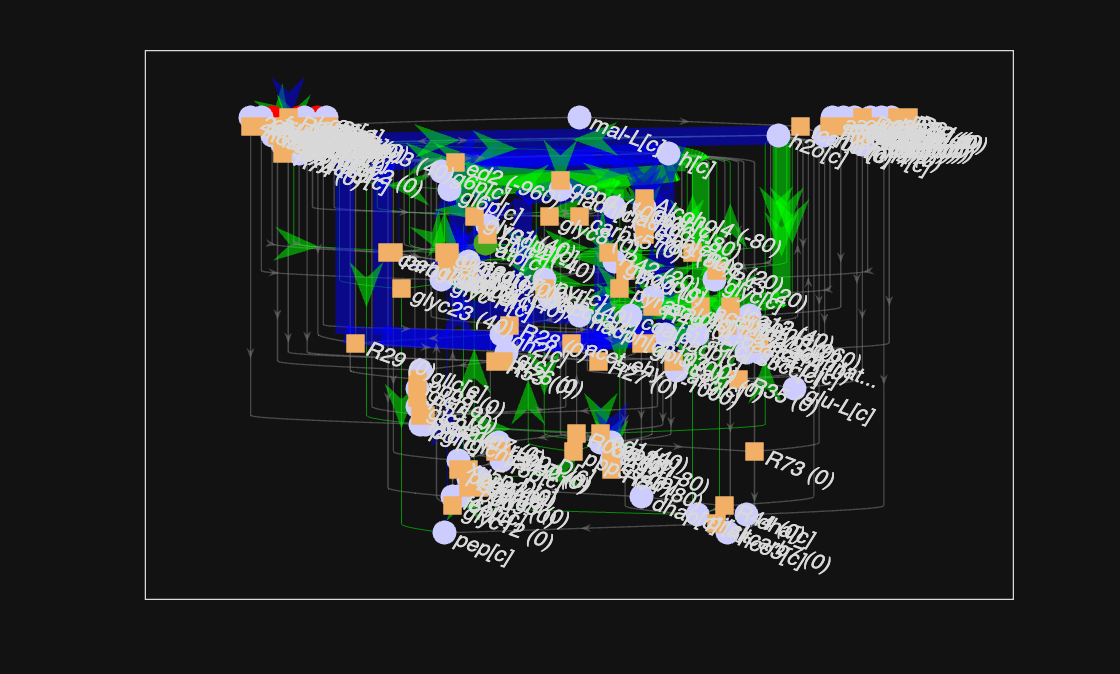

Involved_mets = 78×1 cell array
    {'f6p[c]'   }
    {'g6p[c]'   }
    {'atp[c]'   }
    {'glc-D[c]' }
    {'adp[c]'   }
    {'h[c]'     }
    {'fru[c]'   }
    {'nadp[c]'  }
    {'gl6p[c]'  }
    {'nadph[c]' }
    {'nad[c]'   }
    {'nadh[c]'  }
    {'h2o[c]'   }
    {'pgl[c]'   }
    {'dgp[c]'   }
    {'co2[c]'   }
    {'ru5p-D[c]'}
    {'xu5p-D[c]'}
    {'e4p[c]'   }
    {'g3p[c]'   }
    {'r5p[c]'   }
    {'s7p[c]'   }
    {'pyr[c]'   }
    {'dhap[c]'  }
    {'pi[c]'    }
    {'13dpg[c]' }
    {'3pg[c]'   }
    {'2pg[c]'   }
    {'pep[c]'   }
    {'acald[c]' }


Dead_ends = 3×1 cell array
    {'fru[e]'  }
    {'xyl-D[e]'}
    {'o2[e]'   }


[InvolvedMets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {'atp[c]'}, {''}, FBAsolution.x)

**vi. optional argument *****excludeMets***

This argument represents a list of metabolites (default is empty) that will be excluded from the visualization map of the COBRA model in form of the abbreviations of the metabolites separated by a comma. To save time by not creating the list every time from scratch it is possible to create a *cell *type vector in the MATLAB workspace that contains the static abbreviations of the metabolites in the COBRA model and use it as argument *excludeMets*. 

excludeMets = {'atp[c]', 'nad[c]', 'adp[c]', 'h[c]'}

excludeMets = 1×4 cell array
    {'atp[c]'}    {'nad[c]'}    {'adp[c]'}    {'h[c]'}


Start_time = '2026_3_10_19_4_57.4787'

glyc12	f6p[c] 	->	g6p[c] 
glyc21	atp[c] + glc-D[c] 	->	g6p[c] + adp[c] + h[c] 
carb12	atp[c] + fru[c] 	<=>	f6p[c] + adp[c] + h[c] 
ed2	g6p[c] + nadp[c] 	<=>	h[c] + gl6p[c] + nadph[c] 
g6pd	g6p[c] + nad[c] 	<=>	h[c] + gl6p[c] + nadh[c] 
ed3	gl6p[c] + h2o[c] 	->	h[c] + pgl[c] 
ed1	pgl[c] 	<=>	h2o[c] + dgp[c] 
R035	nadp[c] + pgl[c] 	->	nadph[c] + co2[c] + ru5p-D[c] 
ppp4	xu5p-D[c] + e4p[c] 	<=>	f6p[c] + g3p[c] 
ppp3	xu5p-D[c] + r5p[c] 	<=>	g3p[c] + s7p[c] 
carb2	ru5p-D[c] 	<=>	xu5p-D[c] 
R040	ru5p-D[c] 	<=>	r5p[c] 
ppp5	dgp[c] 	<=>	g3p[c] + pyr[c] 
glyc3	g3p[c] 	<=>	dhap[c] 
glyc1	nad[c] + g3p[c] + pi[c] 	->	h[c] + nadh[c] + 13dpg[c] 
glyc4	atp[c] + 3pg[c] 	<=>	adp[c] + 13dpg[c] 
glyc7	2pg[c] 	<=>	3pg[c] 
glyc23	2pg[c] 	<=>	h2o[c] + pep[c] 
glyc14	atp[c] + pyr[c] 	<=>	adp[c] + h[c] + pep[c] 
pyr_dec	h[c] + pyr[c] 	->	co2[c] + acald[c] 
ed5	nad[c] + pyr[c] + coa[c] 	->	nadh[c] + co2[c] + accoa[c] 
Alcohol4	nad[c] + etoh[c] 	<=>	h[c] + nadh[c] + acald[c] 
acet_dehy	nad[c] + h2o[c] + acald[c

h =   GraphPlot with properties:

     NodeColor: [166×3 double]
    MarkerSize: 8
        Marker: {1×166 cell}
     EdgeColor: [0.5000 0.5000 0.5000]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {1×166 cell}
     EdgeLabel: {}
         XData: [41 60 73.5000 77.5000 53 46 54 63 25 28.5000 31.5000 62.5000 49.5000 21.5000 20.5000 21.5000 56.5000 20.5000 51.5000 37.5000 5 6 9 10 24.5000 84.5000 44 59 83.5000 52 31.5000 62 59.5000 40 67 52.5000 40 39 33.5000 33 51 … ] (1×166 double)
         YData: [13 11 34 35 7 9 9 31 27 19 17 5 5 3 13 15 3 1 15 5 33 31 35 37 7 13 11 13 35 5 35 27 29 35 35 27 9 11 9 7 5 34 3 37 3 23 33 25 3 35 33 11 25 23 21 5 37 36 34 37 37 37 37 37 37 36 37 37 37 37 37 37 37 37 12 33 34 10 10 … ] (1×166 double)
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

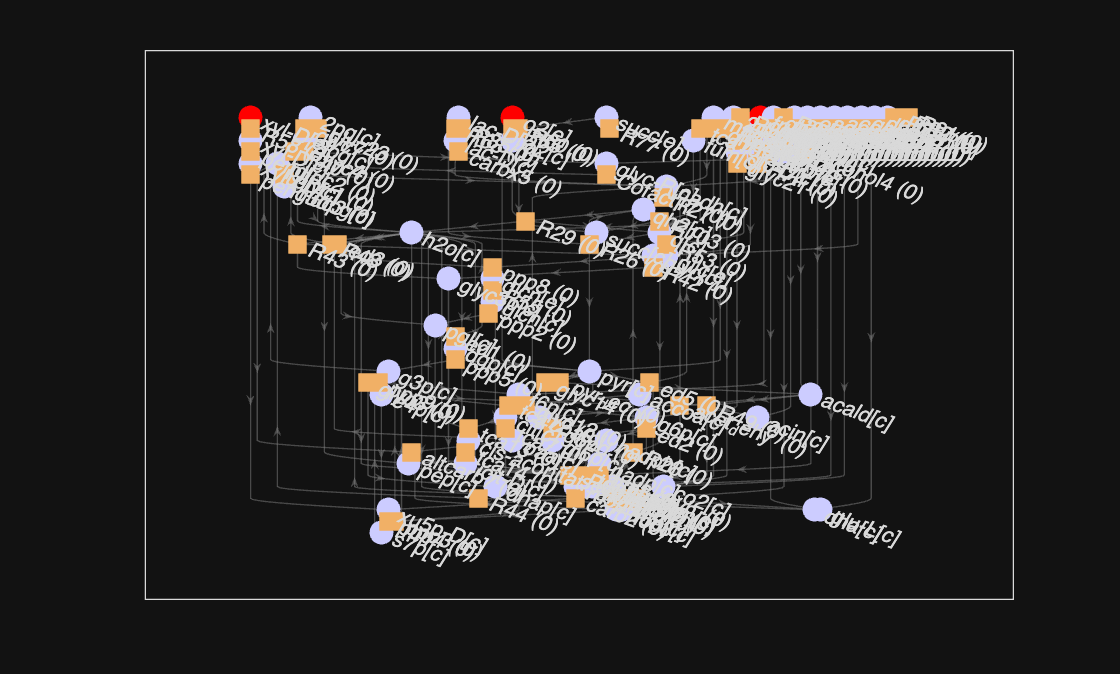

Involved_mets = 74×1 cell array
    {'f6p[c]'   }
    {'g6p[c]'   }
    {'glc-D[c]' }
    {'fru[c]'   }
    {'nadp[c]'  }
    {'gl6p[c]'  }
    {'nadph[c]' }
    {'nadh[c]'  }
    {'h2o[c]'   }
    {'pgl[c]'   }
    {'dgp[c]'   }
    {'co2[c]'   }
    {'ru5p-D[c]'}
    {'xu5p-D[c]'}
    {'e4p[c]'   }
    {'g3p[c]'   }
    {'r5p[c]'   }
    {'s7p[c]'   }
    {'pyr[c]'   }
    {'dhap[c]'  }
    {'pi[c]'    }
    {'13dpg[c]' }
    {'3pg[c]'   }
    {'2pg[c]'   }
    {'pep[c]'   }
    {'acald[c]' }
    {'coa[c]'   }
    {'accoa[c]' }
    {'etoh[c]'  }
    {'ac[c]'    }


Dead_ends = 3×1 cell array
    {'fru[e]'  }
    {'xyl-D[e]'}
    {'o2[e]'   }


[InvolvedMets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, excludeMets)

The main idea of this argument is to ensure possibility to exclude very employed metabolites (e.g., h, h2o, atp, adp, nad etc.) to avoid unnecessary mesh on the map (see Fig. 4, Fig. 5, Fig. 6, Fig. 7, Fig. 8 and Fig. 9).

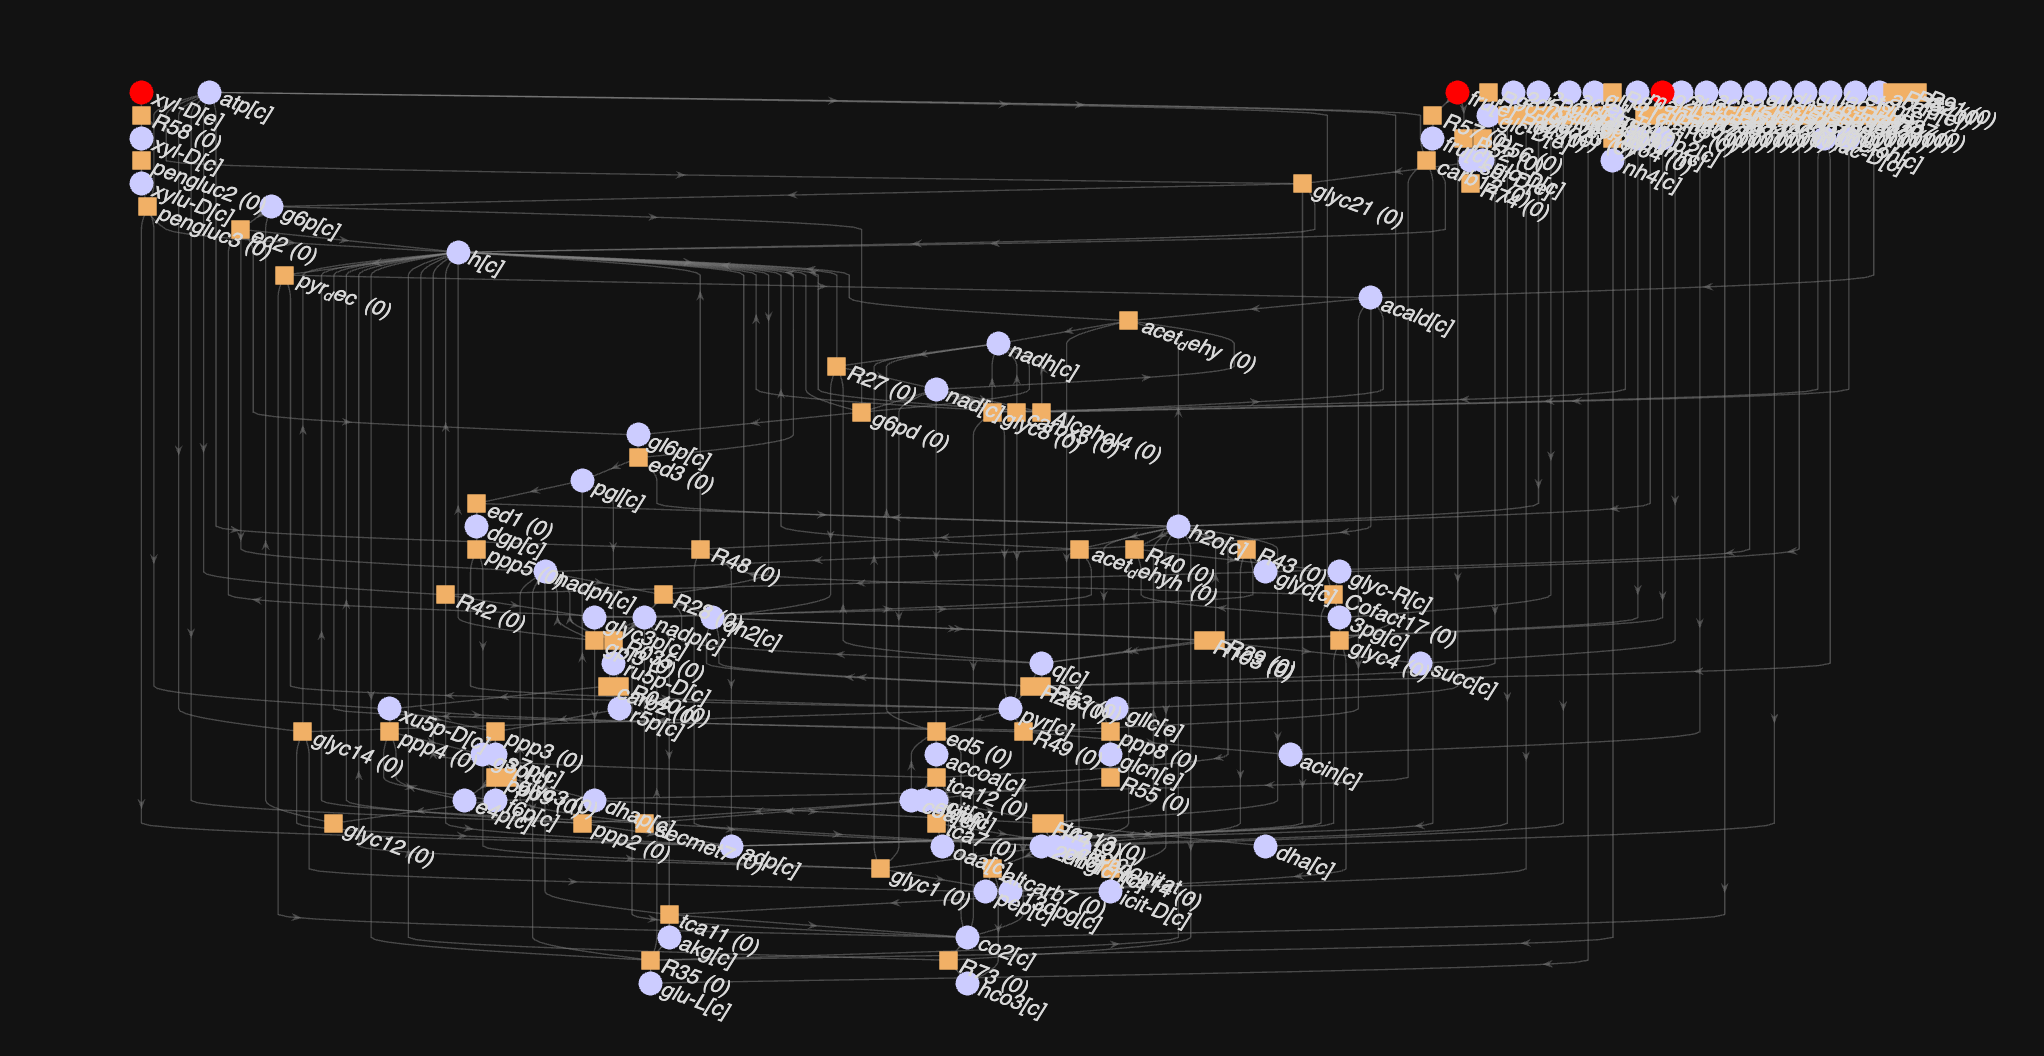

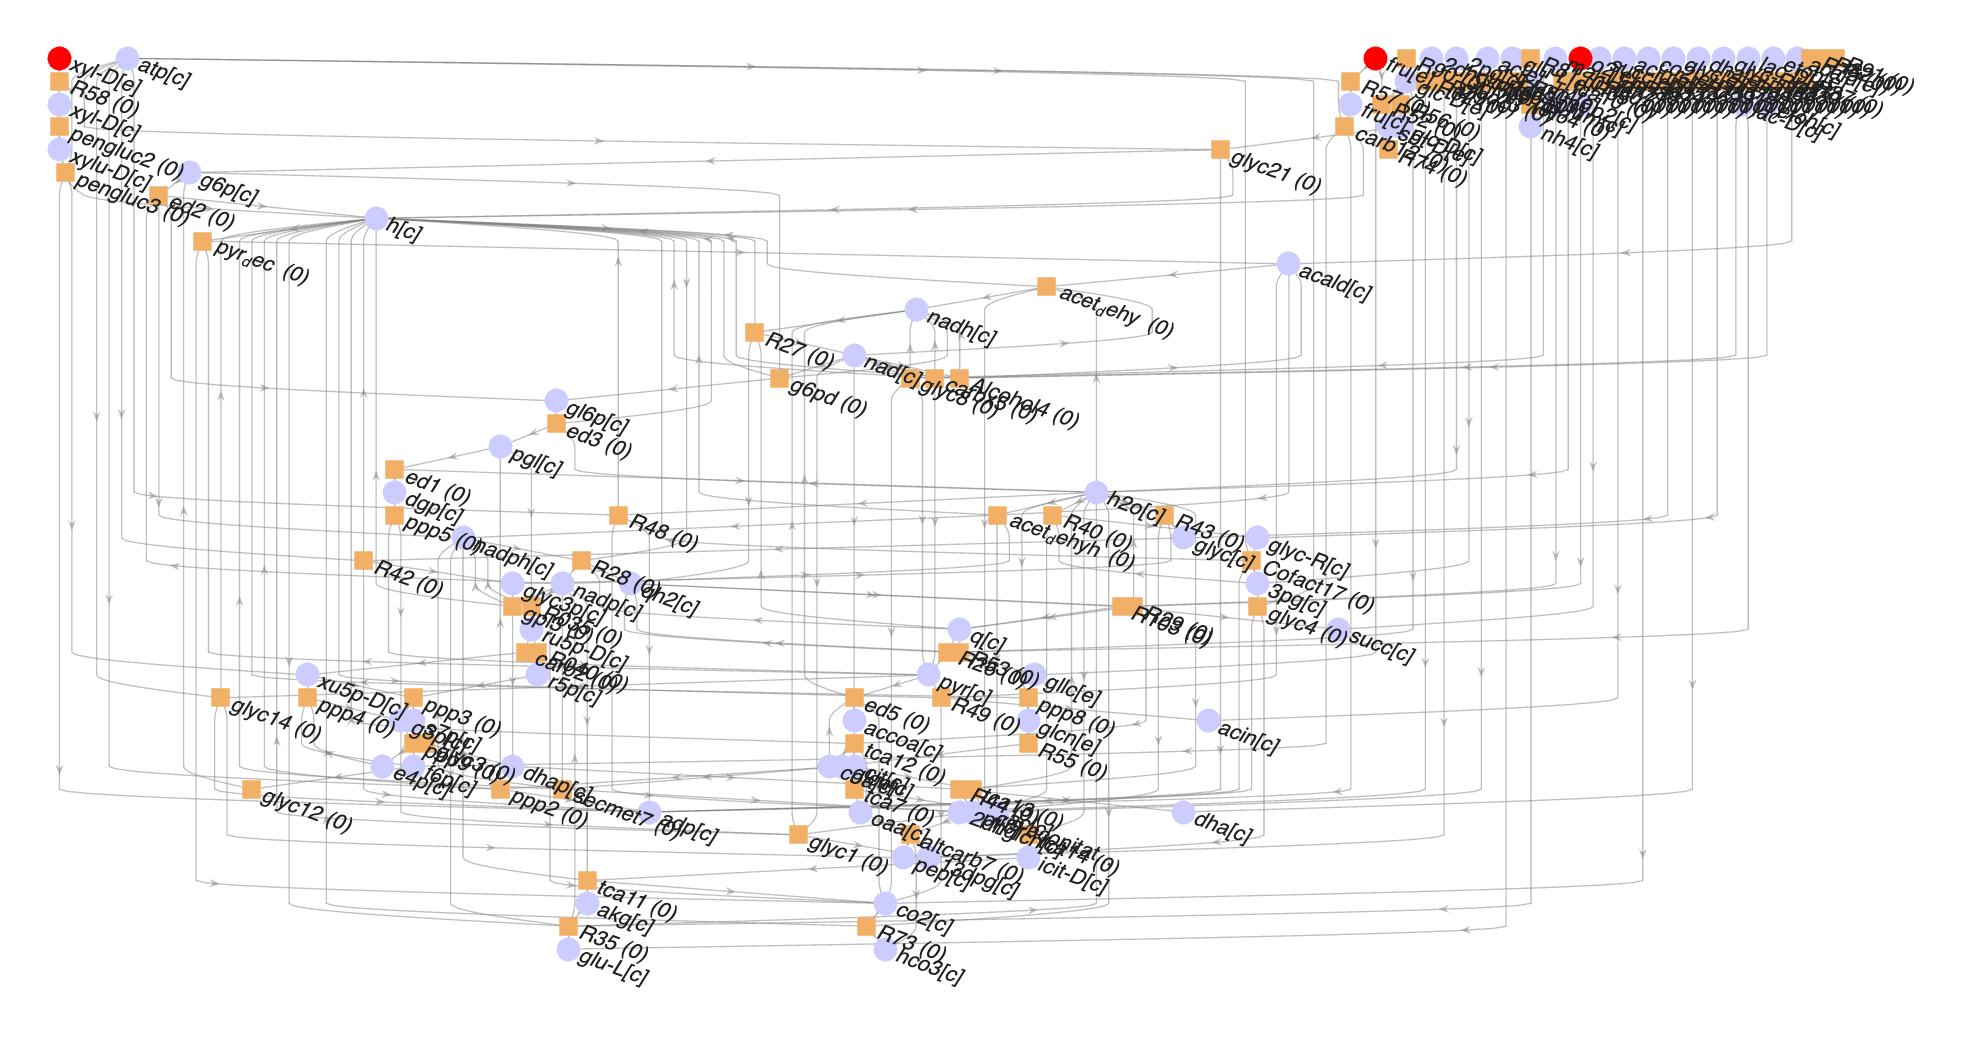

**Fig. 4.** An example of the map of the COBRA model. Full scope. 

>>[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc')

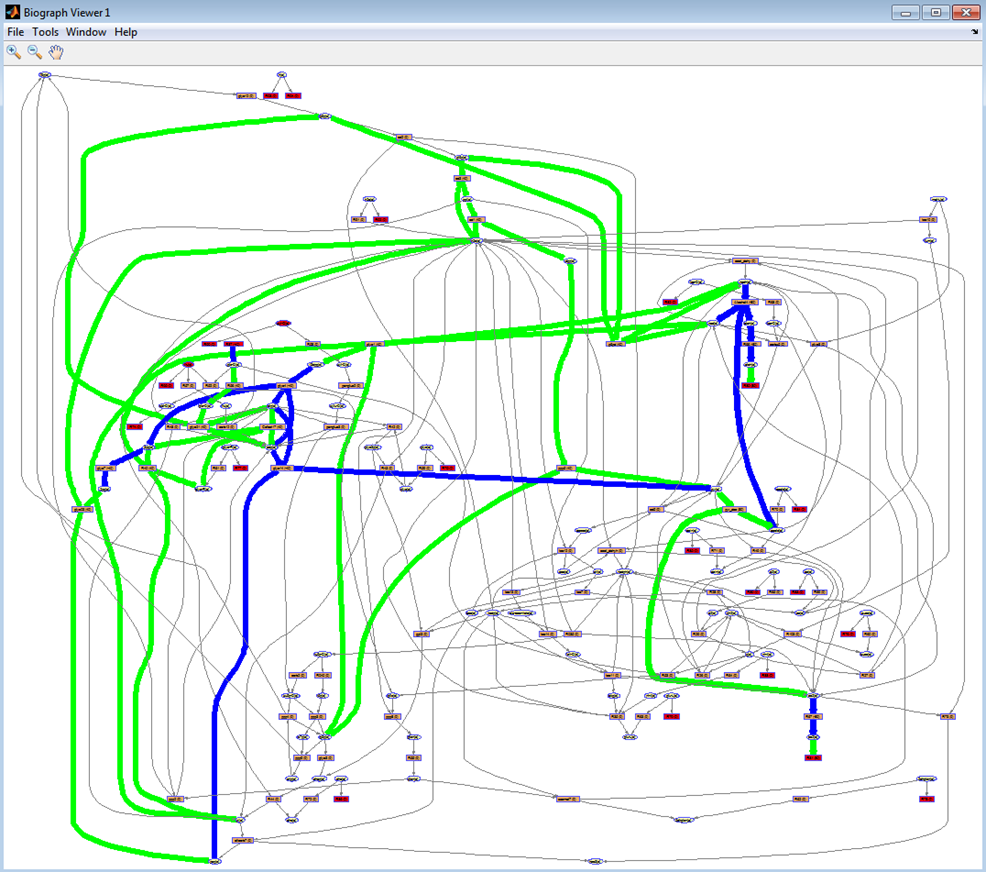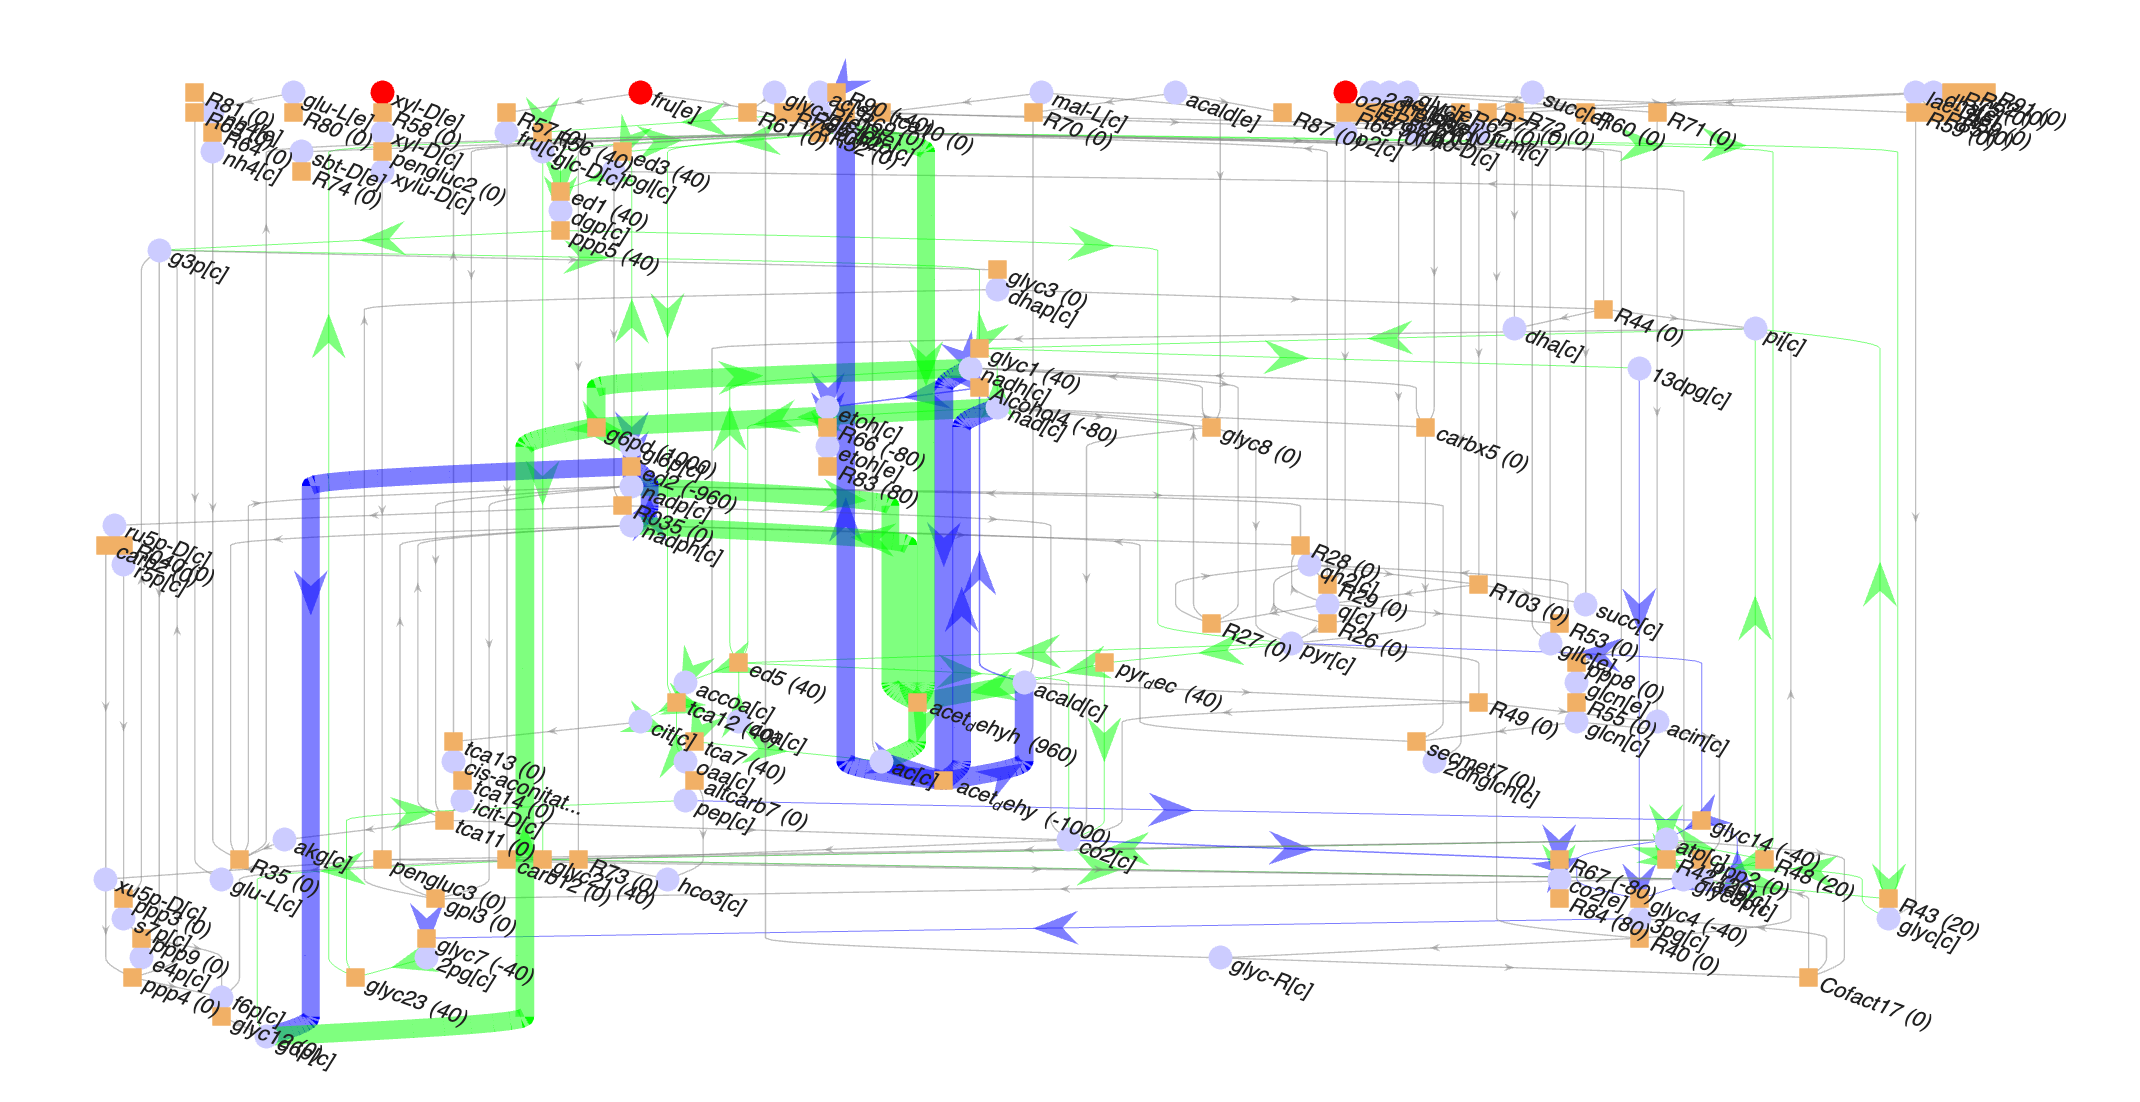

**Fig. 5.** An example of the map of the COBRA model. The metabolite *h[c]* is excluded from map which reduce the number of edges by 26.

>>[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, {'h[c]'}, FBAsolution.x)

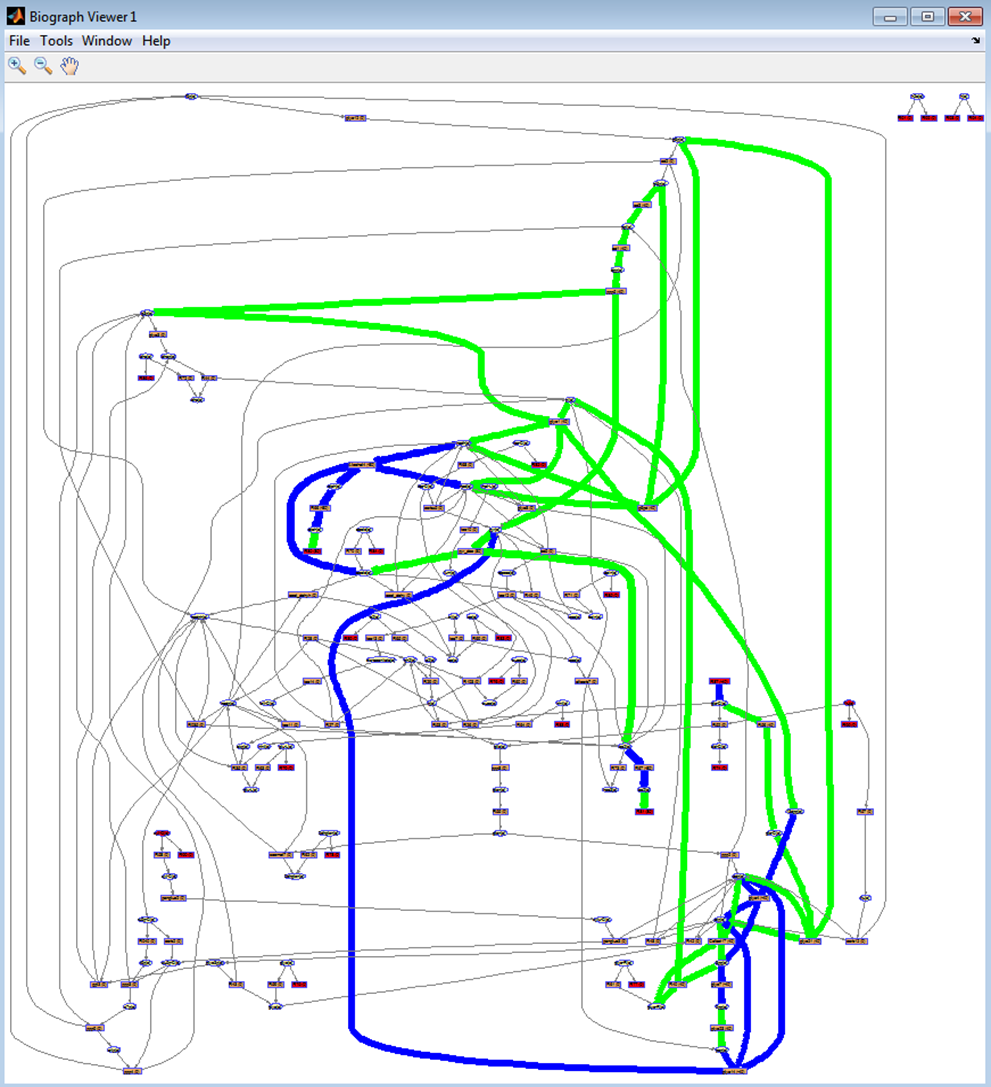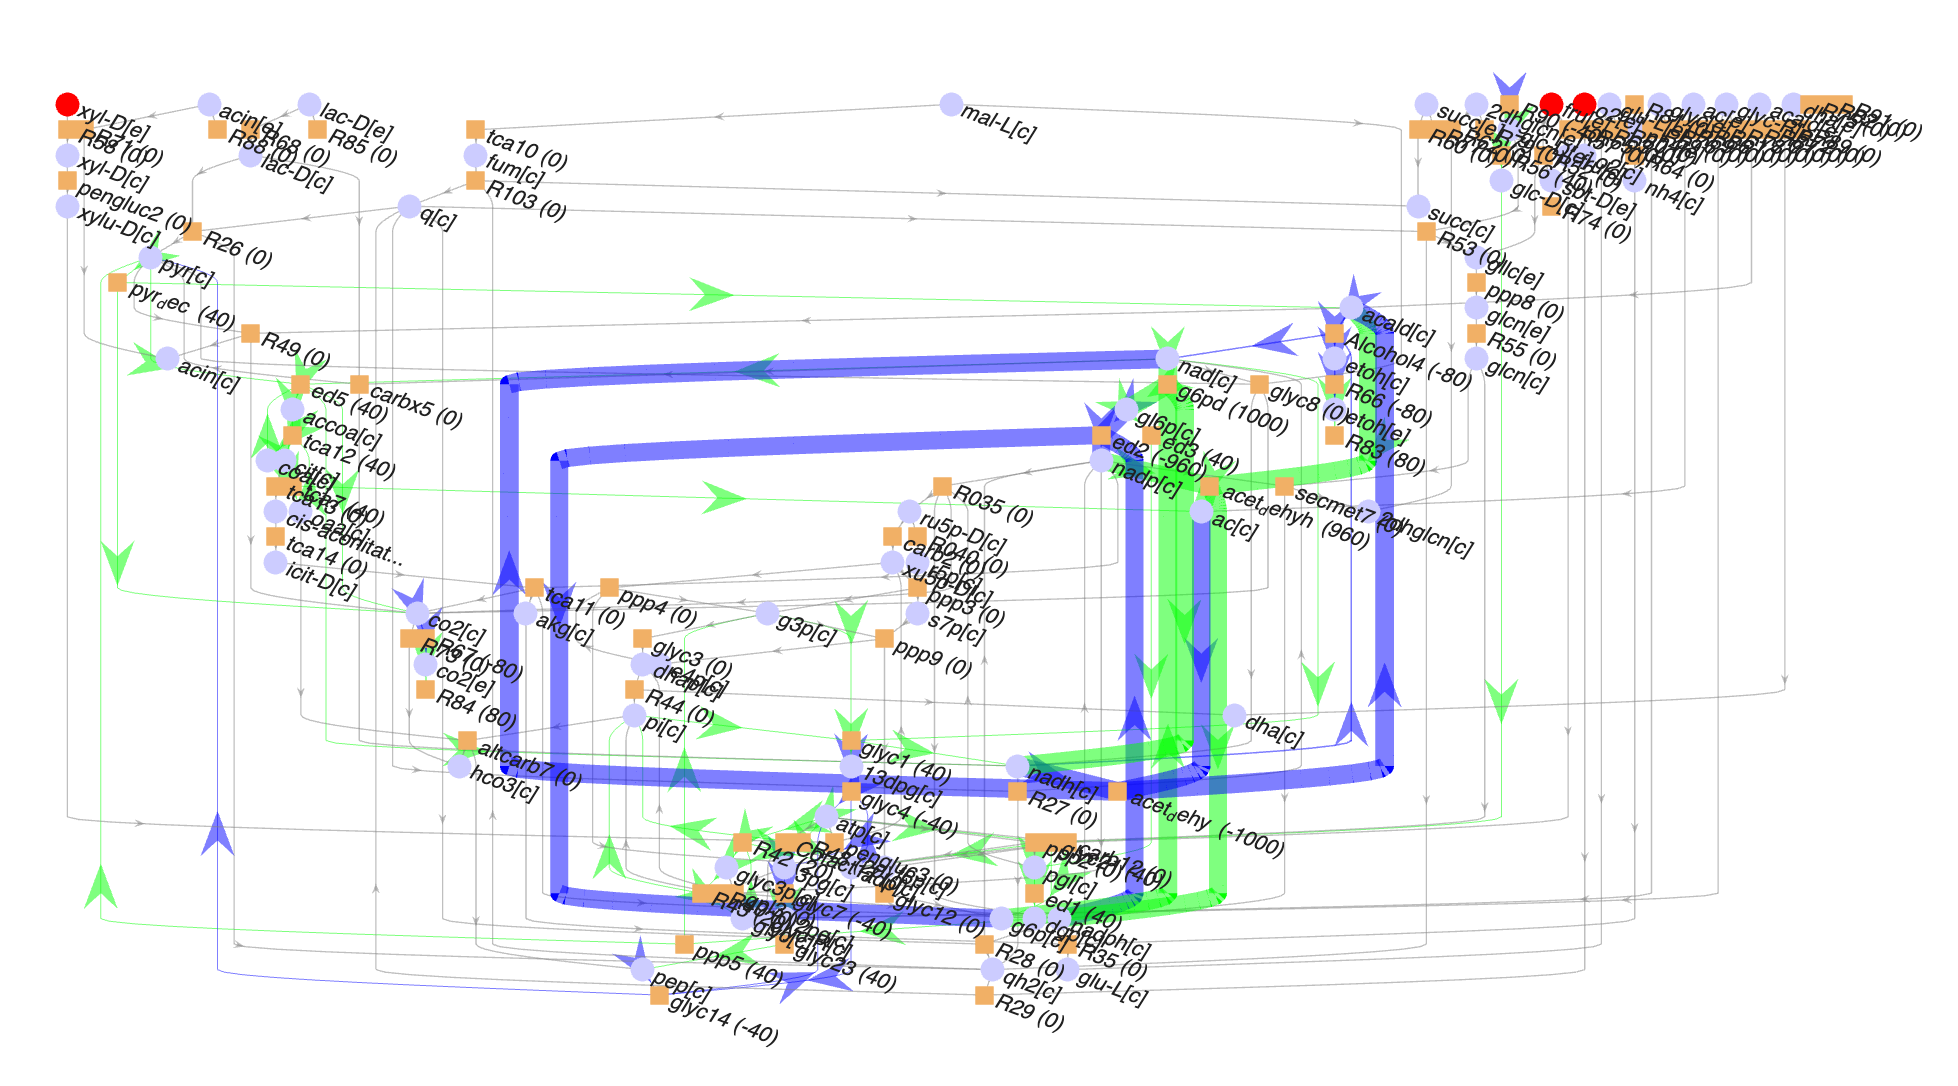

**Fig. 6.** An example of the map of the COBRA model. The metabolites *h[c]*, and *h2o[c]* are excluded from map which reduce the number of edges by 26+17=43.

>>[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, {'h[c]', 'h2o[c]'}, FBAsolution.x)

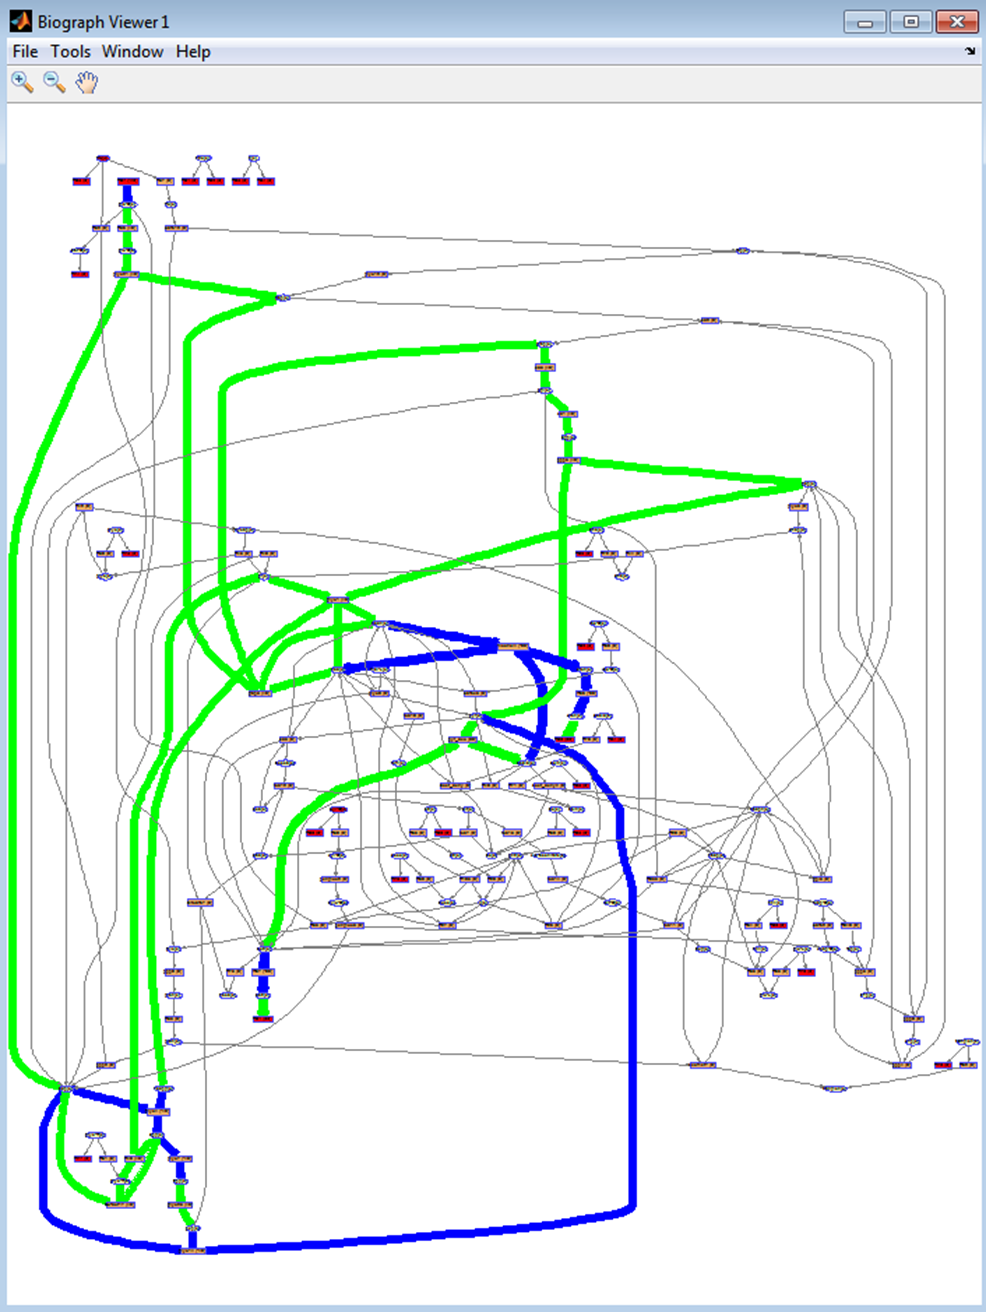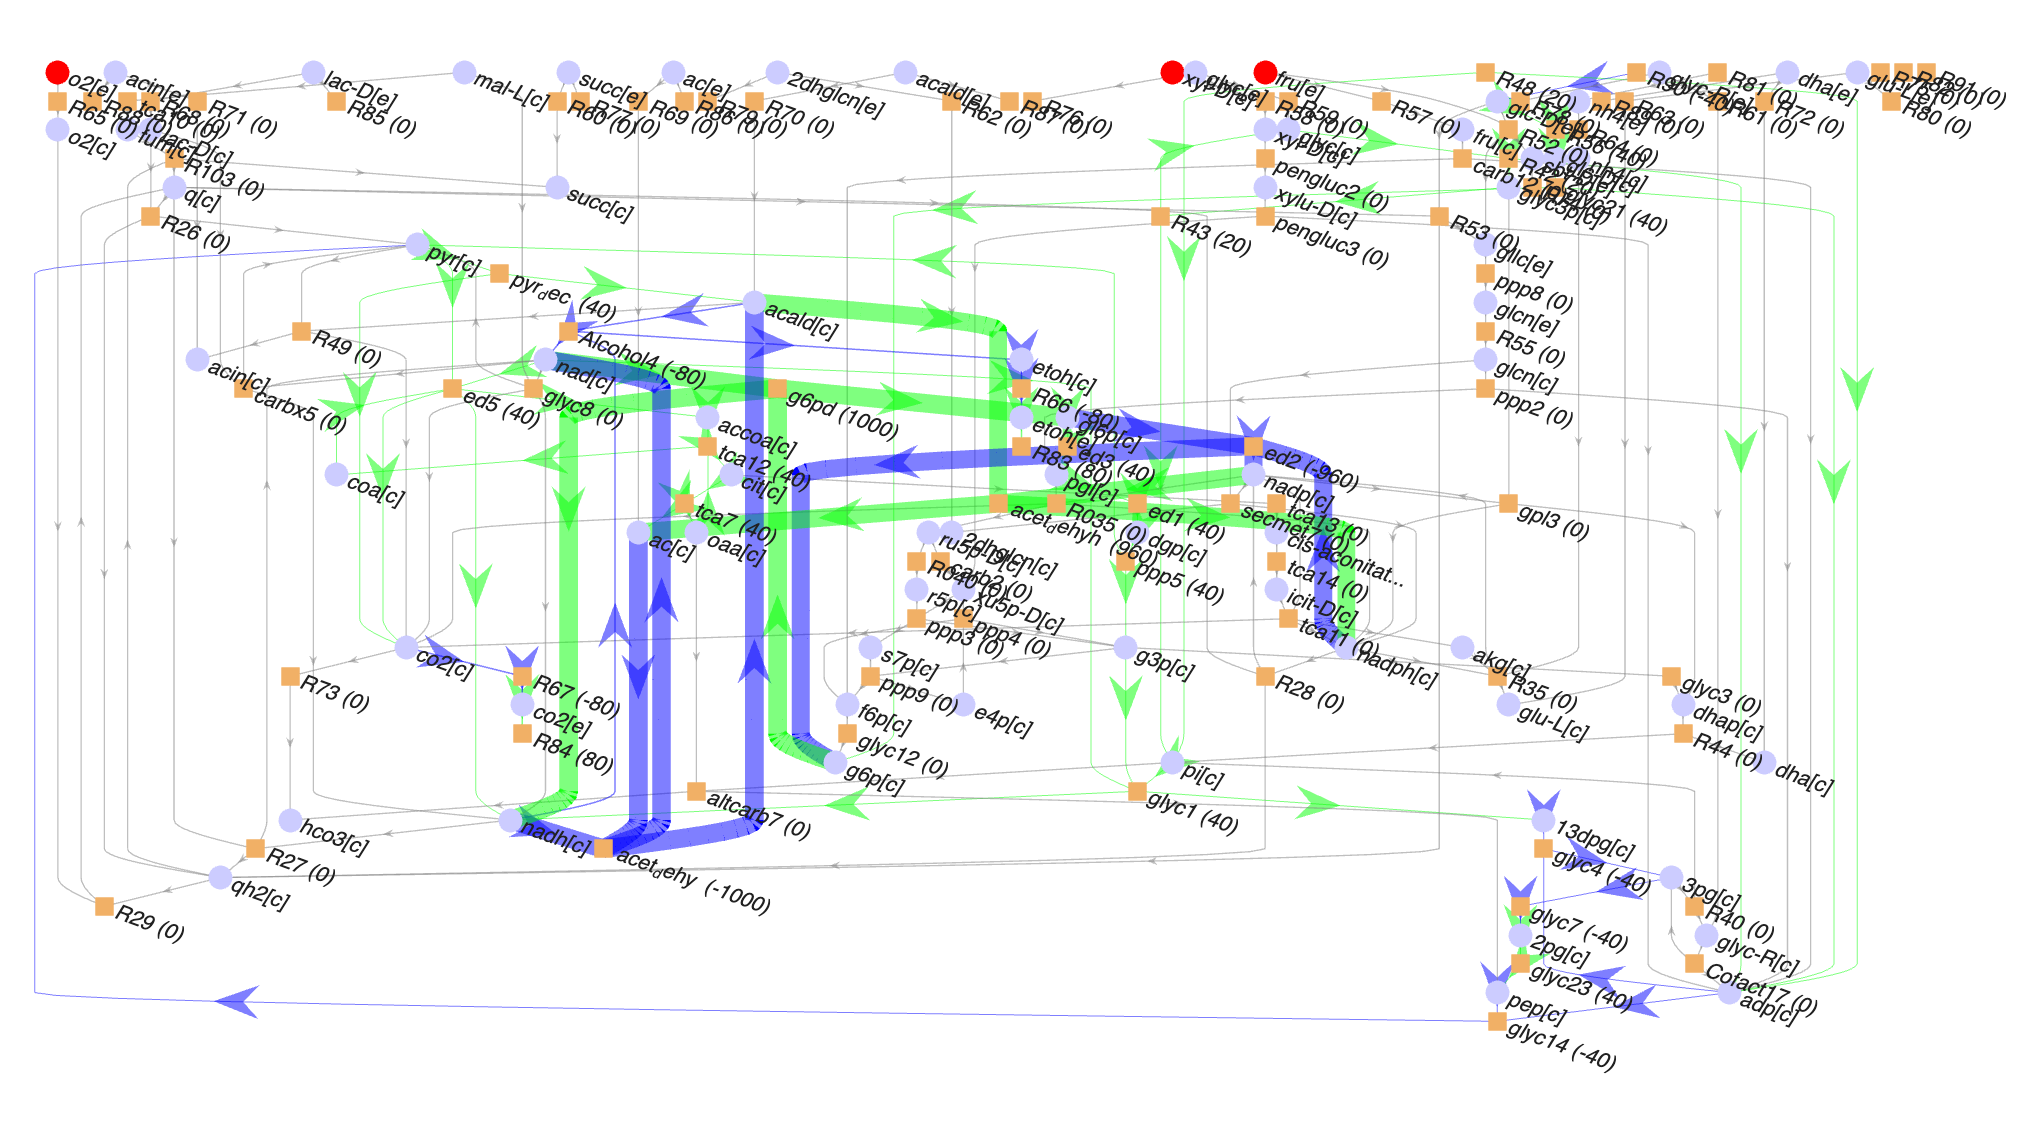

**Fig. 7. **An example of the map of the COBRA model. The metabolites *h[c]*, *h2o[c]*, and *atp[c]* are excluded from map which reduce the number of edges by 26+17+9=52.

>>[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, {'h[c]', 'h2o[c]', 'atp[c]'}, FBAsolution.x)

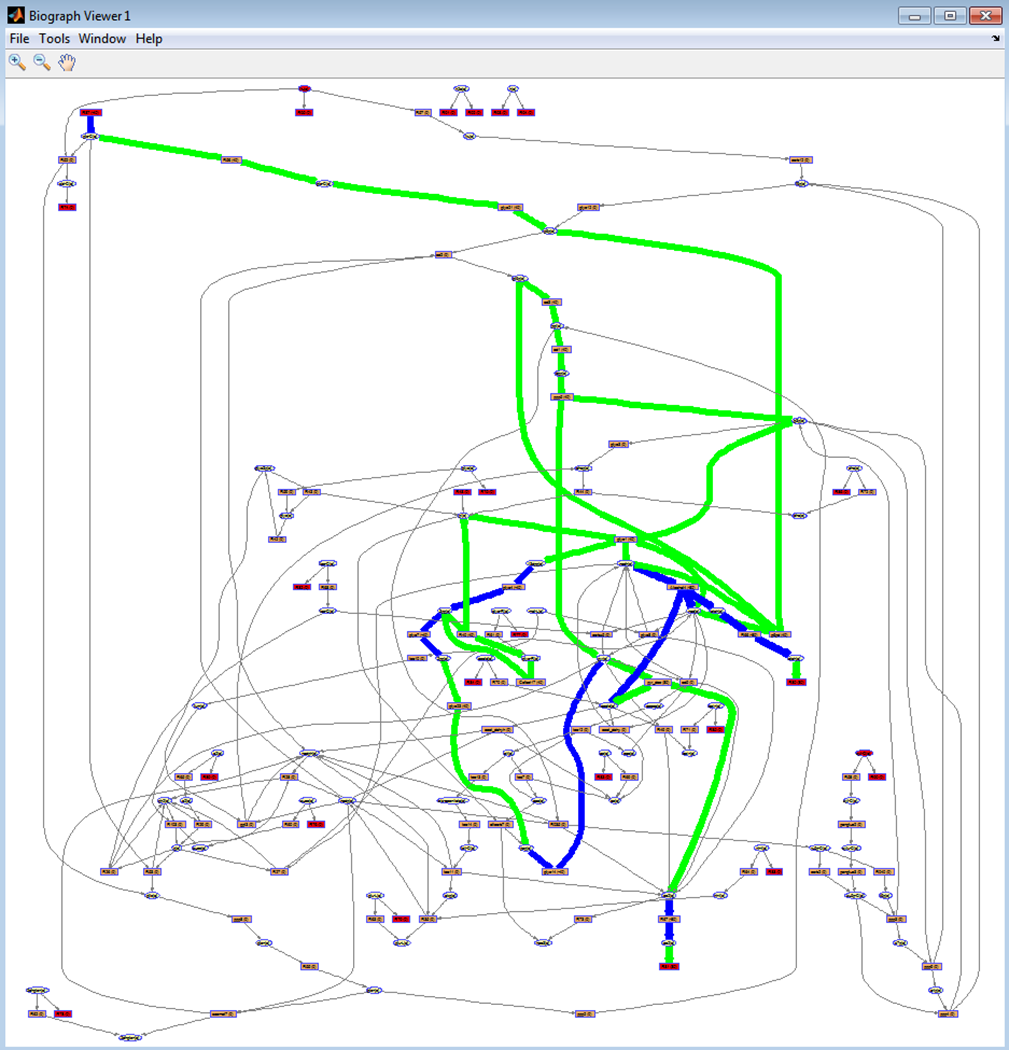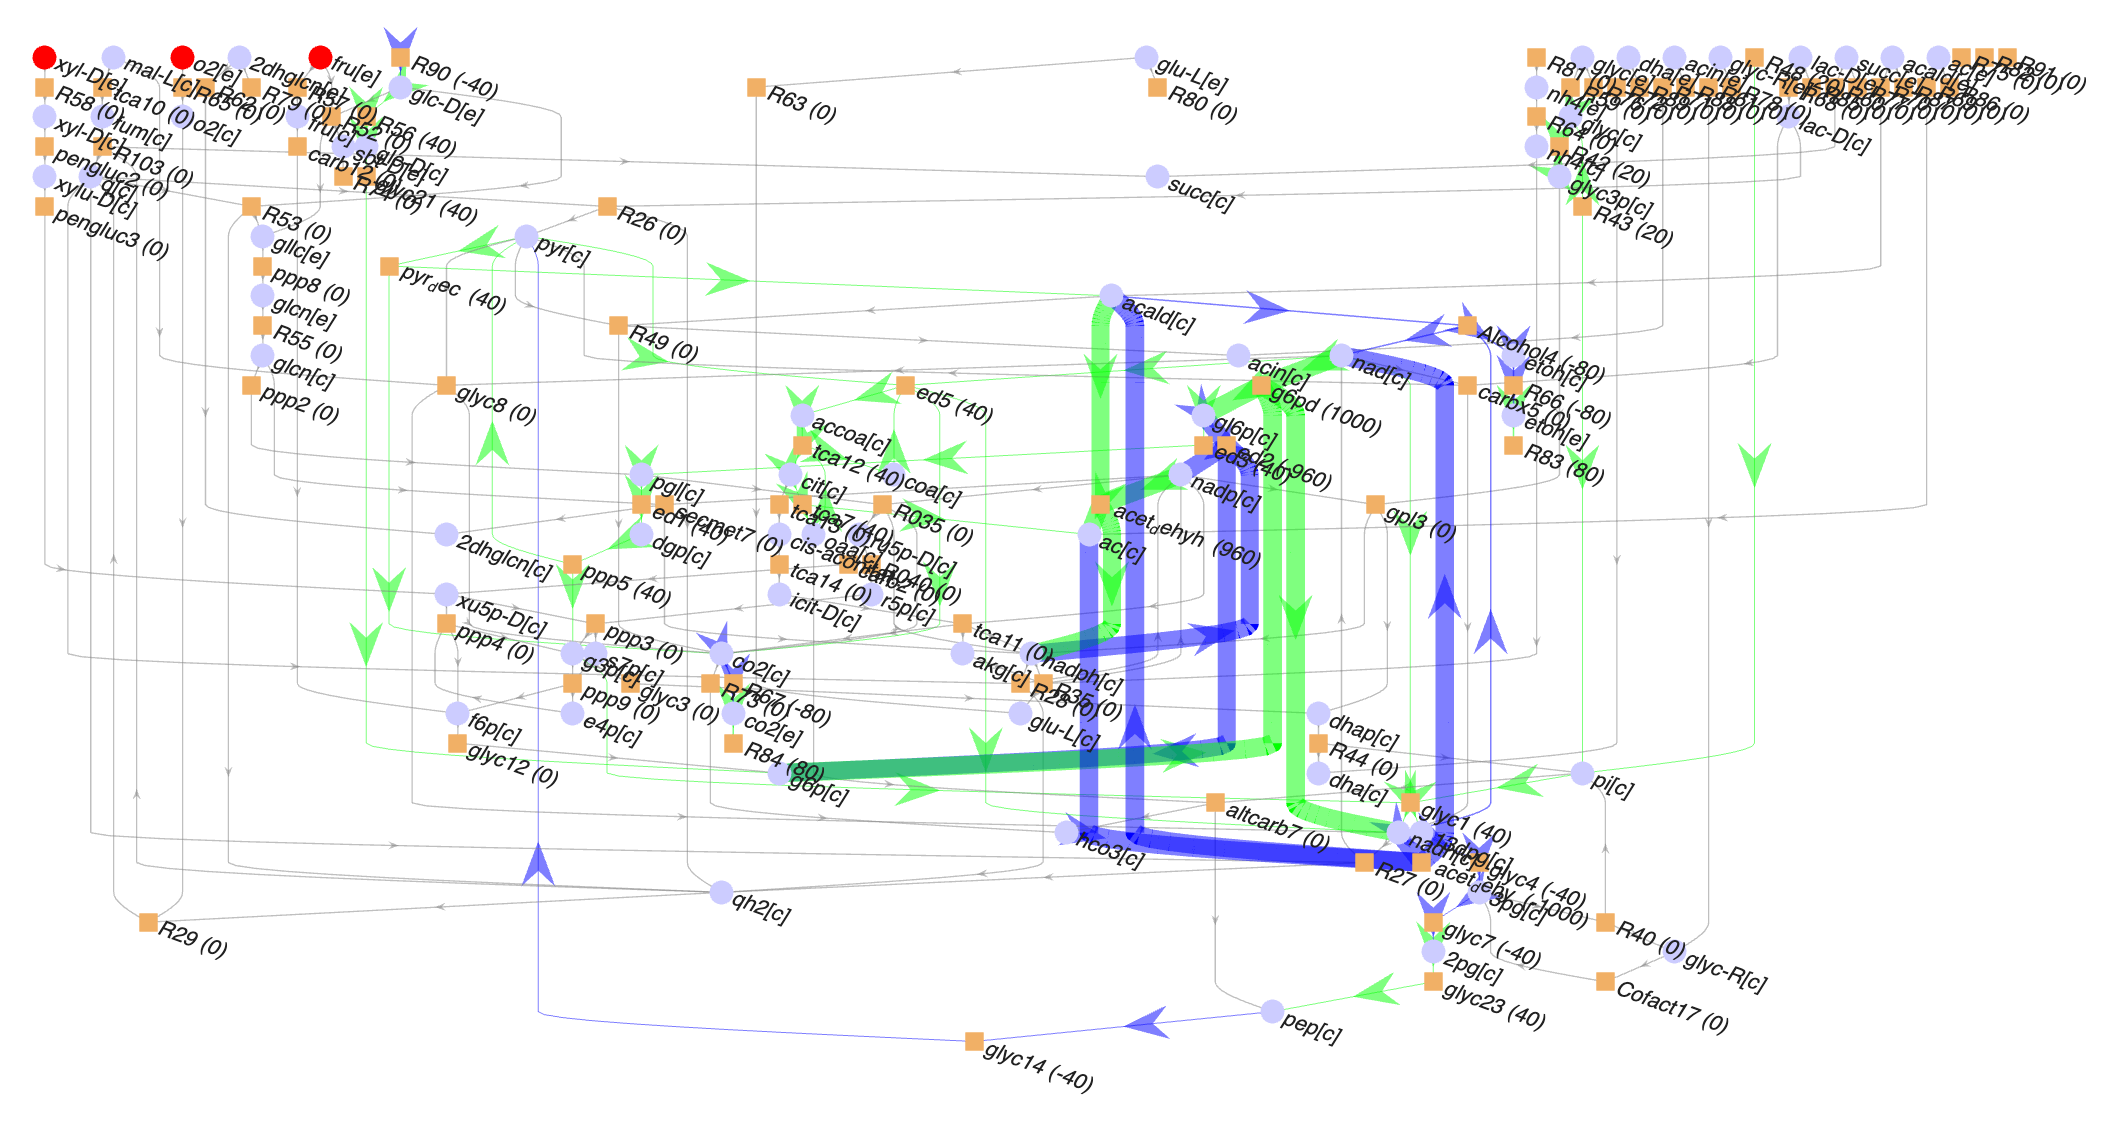

**Fig. 8.** An example of the map of the COBRA model. The metabolites *h[c]*, *h2o[c]*, *atp[c]*, and *adp[c]* are excluded from map which reduce the number of edges by 26+17+9+9=61.

>>[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, {'h[c]', 'h2o[c]', 'atp[c]', 'adp[c]'}, FBAsolution.x)

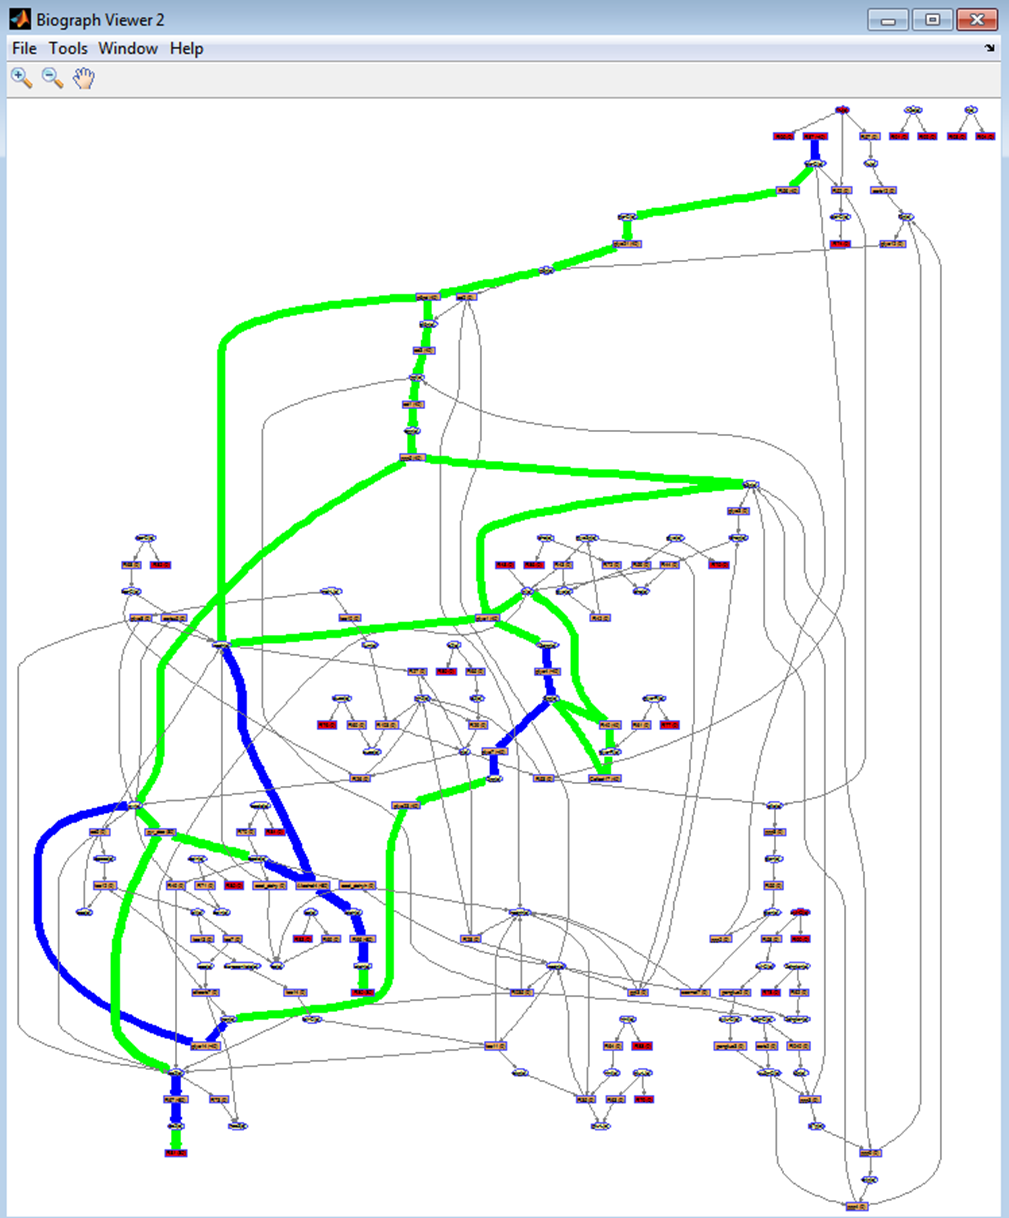

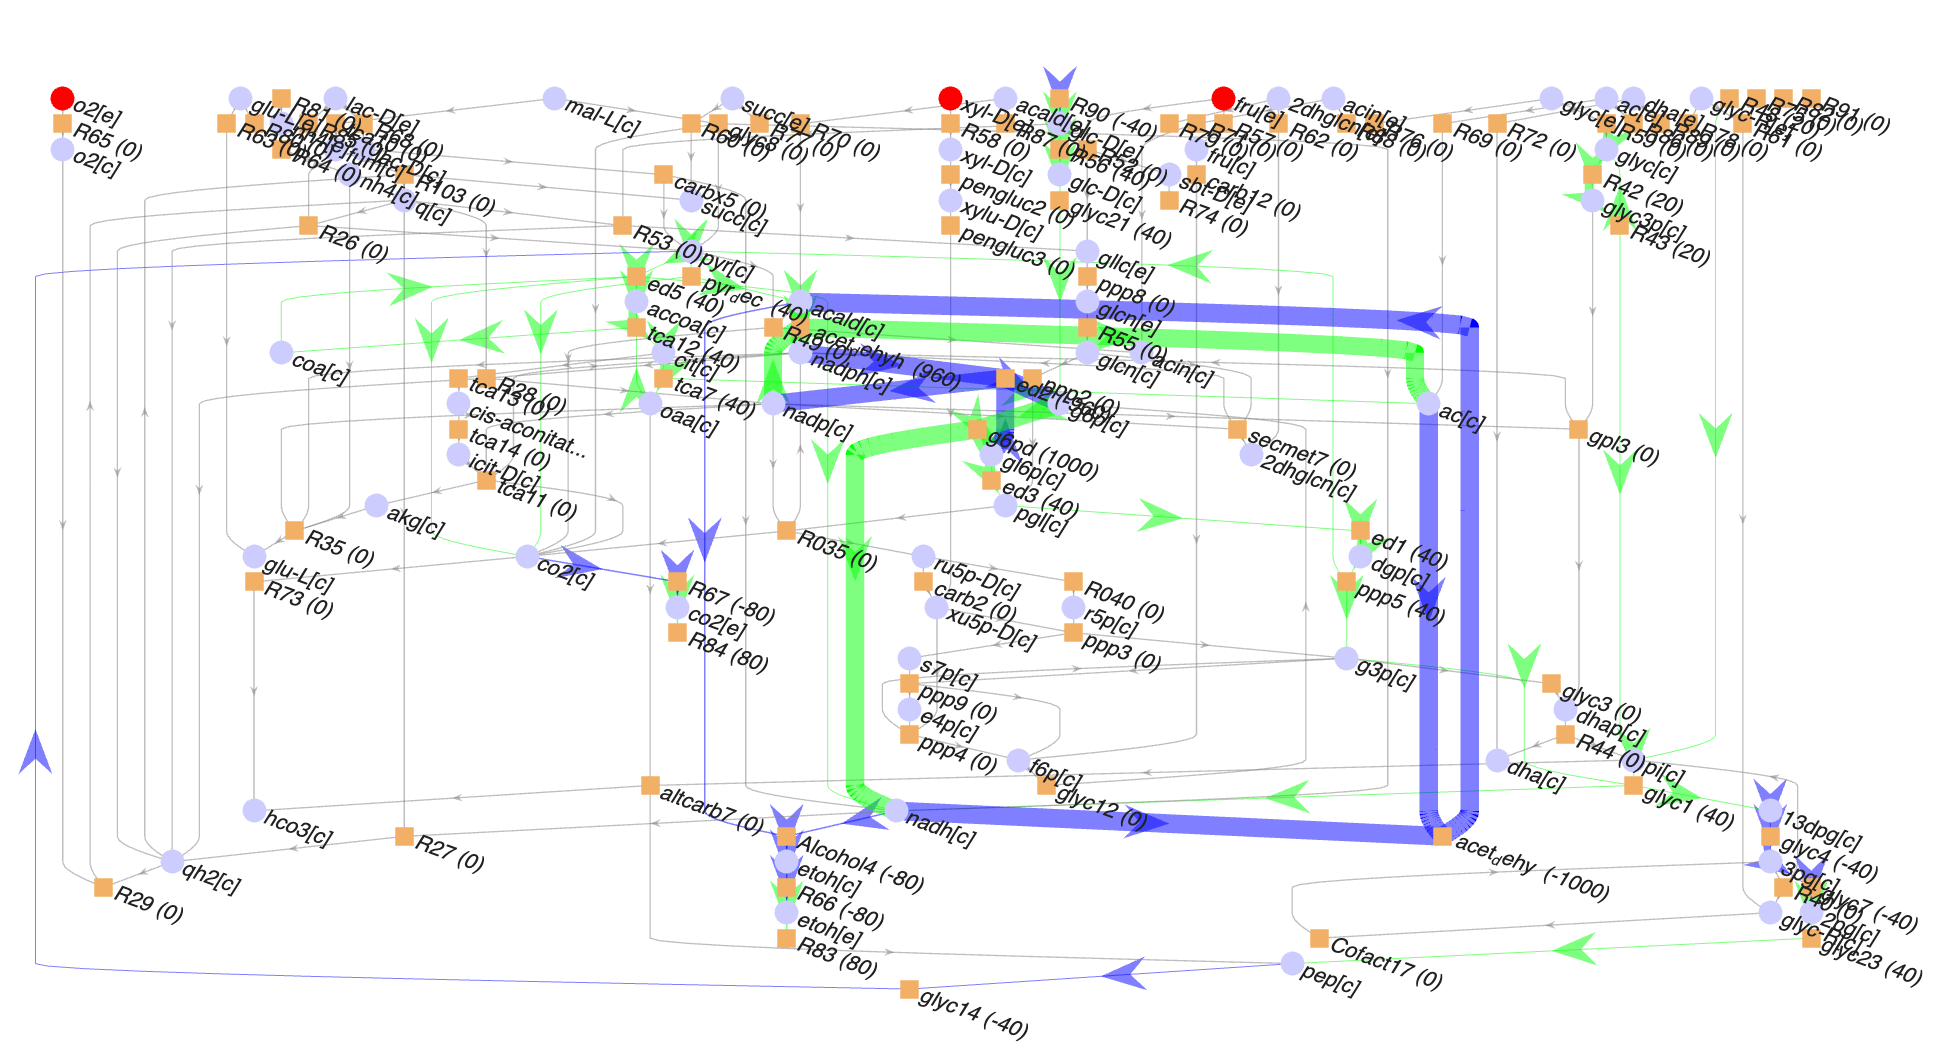

**Fig. 9.** An example of the map of the COBRA model. The metabolites *h[c]*, *h2o[c]*, *atp[c]*, *adp[c]*, and *nad[c]* are excluded from map which reduce the number of edges by 26+17+9+9+8=69.

>>[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, {'h[c]', 'h2o[c]', 'atp[c]', 'adp[c]', 'nad[c]'}, FBAsolution.x)

**vii. optional argument *****flux***

It is a *double* type Nx1 size vector of fluxes of reactions where N is number of reactions (default is vector of x). This vector is calculated during the optimization of the objective function and can be accessed through the result of the optimization command.

FBAsolution.x

ans =            0
          40
           0
        -960
        1000
          40
          40
           0
           0
           0
           0
           0
          40
           0
          40


## ***Output of the command bio_draw_by_rxn***

The command bio_draw_by_rxn has two output vectors in the result: *involvedMets *and *deadEnds*.

**i. the vector *****involvedMets***

It is a *cell *type vector that contains a list of the involved metabolites in the specified reactions (see Fig. 10).

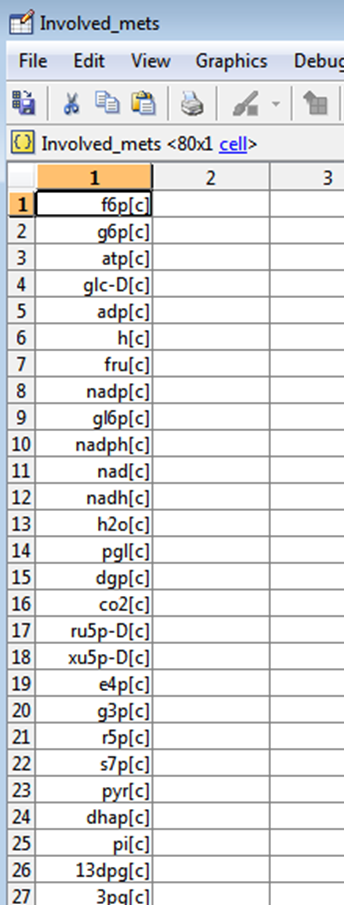

**Fig. 10.** An example of the list of the involved metabolites.

**ii. the vector *****deadEnds***

It is also a *cell *type vector but it contains a list of the dead end metabolites in the specified reactions (see Fig. 11).

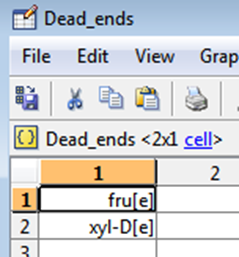

**Fig. 11. **An example of the list of the dead end metabolites.

## *Application of command**** draw_by_met*** 

***draw_by_met*** can be performed but does need flux data, and so will need wither a viable model or a flux space of 0 values equal to the reactions in the model (See Fig. 12).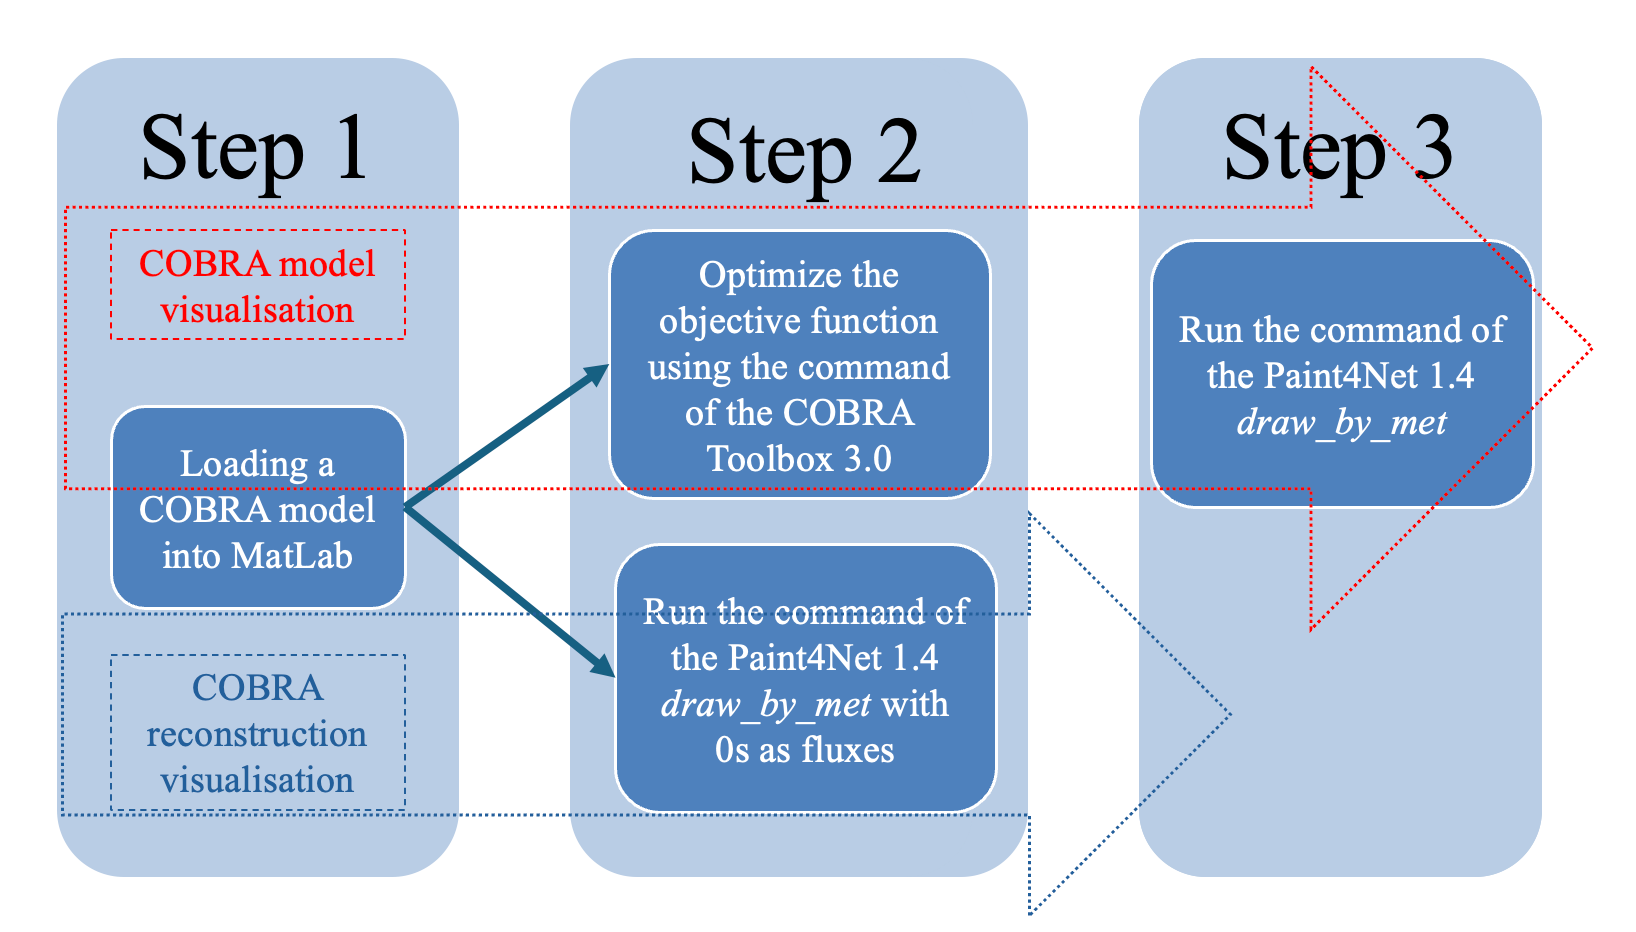

**Fig. 12. **The scenarios of an application of the command *draw_by_met*.

## **Input arguments of the command *****draw_by_met***

### NOTE

Unlike in previous releases of Paint4Net, which relied on the now depreciated **Biograph** function, in recent releases the *draw_by_met *function now requires flux data in order to plot metabolite links and reactions within a model.

The command *draw_by_met *has several input arguments – *model, **metAbbr**, drawMap, radius, direction, excludeMets, *and *flux*. The last 5 were optional in previous releases, but need to be included in recent releases.

If using previous versions of MatLab that have access to the biograph funtion, it means that the algorithm of the command *draw_by_met *uses default values of those arguments, so the user can ignore them if additional functionality is not necessary.

**i. argument *****model***

This argument stands for a COBRA model in the MATLAB workspace.Load the model and create an FBASolution object, as before, or your model, the model argument represents your model of interest.

**ii. argument *****metAbbr***

It is a *cell *type variable that can take a value that represents the abbreviation of a metabolite in a COBRA model. This argument is the start point for the algorithm of the command *draw_by_met* for visualization, however, alone creates empty cells as a result

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'etoh[c]'})

**iii.** For successful execution of the command *[directionRxns, involvedMets, deadEnds] = draw_by_met(model, metAbbr, drawMap, radius, direction, excludeMets, flux)* the other arguments are necessary.

These required arguments are:

- ***metAbbr -*** metabolite of interest

- ***drawmap - ***True or False based on if you want visual output or not

- **radius - **It is a *double* type variable that can take a value of natural numbers (1,2,3…n).

- **direction -** visualize structure (struc) visualize substrates (sub), products (prod) or substrates and products (both)

- **excludeMets - **metabolites to exclude from graph

- **flux - **FBAsolution values (FBAsolution.x)

More detaied descriptions of the arguments will follow. 

Start_time = '2026_3_10_19_5_52.2748'

Alcohol4	nad[c] + etoh[c] 	<=>	h[c] + nadh[c] + acald[c] 
R66	etoh[e] 	<=>	etoh[c] 
glyc21	atp[c] + glc-D[c] 	->	g6p[c] + adp[c] + h[c] 
ed2	g6p[c] + nadp[c] 	<=>	h[c] + gl6p[c] + nadph[c] 
g6pd	g6p[c] + nad[c] 	<=>	h[c] + gl6p[c] + nadh[c] 
ed3	gl6p[c] + h2o[c] 	->	h[c] + pgl[c] 
glyc1	nad[c] + g3p[c] + pi[c] 	->	h[c] + nadh[c] + 13dpg[c] 
glyc14	atp[c] + pyr[c] 	<=>	adp[c] + h[c] + pep[c] 
pyr_dec	h[c] + pyr[c] 	->	co2[c] + acald[c] 
ed5	nad[c] + pyr[c] + coa[c] 	->	nadh[c] + co2[c] + accoa[c] 
acet_dehy	nad[c] + h2o[c] + acald[c] 	<=>	2 h[c] + nadh[c] + ac[c] 
acet_dehyh	nadp[c] + h2o[c] + acald[c] 	<=>	2 h[c] + nadph[c] + ac[c] 
tca12	h2o[c] + accoa[c] + oaa[c] 	<=>	h[c] + coa[c] + cit[c] 
R42	atp[c] + glyc[c] 	<=>	adp[c] + h[c] + glyc3p[c] 
R48	atp[c] + h2o[c] 	->	adp[c] + h[c] + pi[c] 
R83	etoh[e] 	->	
Metabolite nodes - light blue: Reaction nodes - Orange


h =   GraphPlot with properties:

     NodeColor: [44×3 double]
    MarkerSize: 8
        Marker: {1×44 cell}
     EdgeColor: [76×3 double]
     LineWidth: [7 0.2800 0.1400 0.1400 0.2800 0.2800 0.5600 6.7200 0.2800 0.2800 7 6.7200 6.7200 0.2800 6.7200 7 0.2800 0.2800 0.5600 7 0.2800 6.7200 0.2800 0.1400 0.2800 0.2800 0.2800 0.2800 0.2800 0.5600 6.7200 0.2800 0.2800 0.5600 7 … ] (1×76 double)
     LineStyle: '-'
     NodeLabel: {1×44 cell}
     EdgeLabel: {}
         XData: [8 25.5000 19.5000 26 17 4.5000 4 7 12.5000 15 13 4.5000 12.5000 18.5000 10.5000 18 19 20.5000 8 22 9.5000 10.5000 31 23 23 27 29 10.5000 10.5000 10.5000 19.5000 2.5000 13 4.5000 18 20 10 13.5000 13 7.5000 22 27 25 10.5000]
         YData: [19 7 21 9 17 1 17 3 15 13 11 9 5 21 7 9 13 21 5 9 5 15 3 21 9 5 21 13 16 14 20 2 18 10 14 8 6 6 12 4 10 6 10 12]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

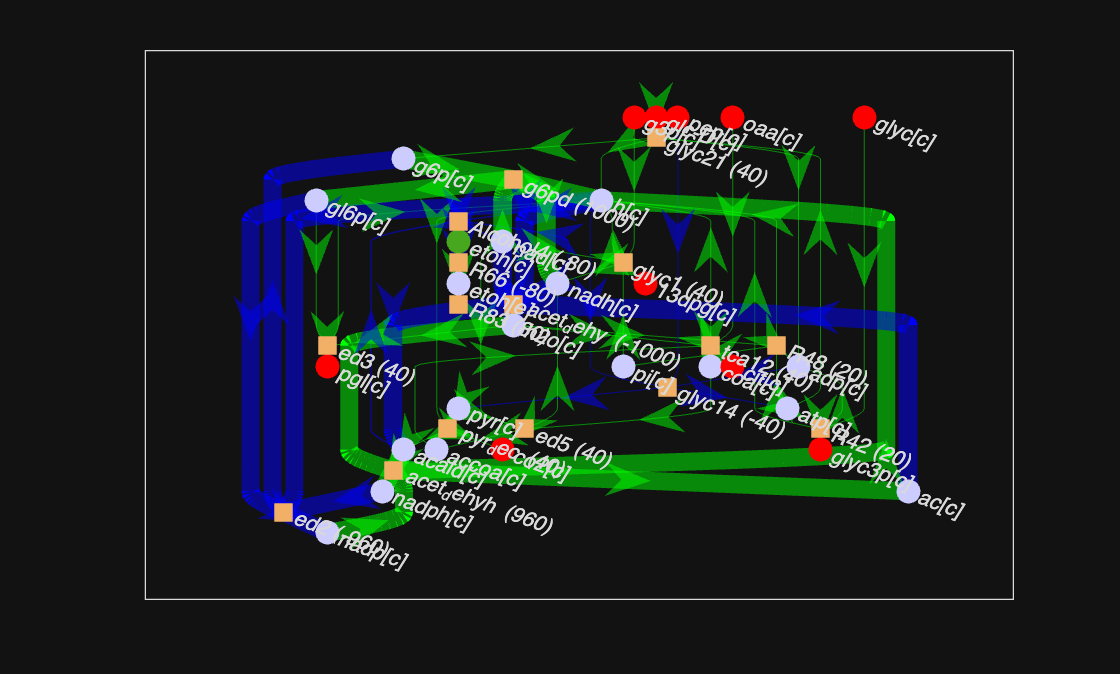

directionRxns = 16×1 cell array
    {'Alcohol4'  }
    {'R66'       }
    {'glyc21'    }
    {'ed2'       }
    {'g6pd'      }
    {'ed3'       }
    {'glyc1'     }
    {'glyc14'    }
    {'pyr_dec'   }
    {'ed5'       }
    {'acet_dehy' }
    {'acet_dehyh'}
    {'tca12'     }
    {'R42'       }
    {'R48'       }
    {'R83'       }


involvedMets = 28×1 cell array
    {'g6p[c]'   }
    {'atp[c]'   }
    {'glc-D[c]' }
    {'adp[c]'   }
    {'h[c]'     }
    {'nadp[c]'  }
    {'gl6p[c]'  }
    {'nadph[c]' }
    {'nad[c]'   }
    {'nadh[c]'  }
    {'h2o[c]'   }
    {'pgl[c]'   }
    {'co2[c]'   }
    {'g3p[c]'   }
    {'pyr[c]'   }
    {'pi[c]'    }
    {'13dpg[c]' }
    {'pep[c]'   }
    {'acald[c]' }
    {'coa[c]'   }
    {'accoa[c]' }
    {'etoh[c]'  }
    {'ac[c]'    }
    {'oaa[c]'   }
    {'cit[c]'   }
    {'glyc3p[c]'}
    {'glyc[c]'  }
    {'etoh[e]'  }


deadEnds = 10×1 cell array
    {'glc-D[c]' }
    {'pgl[c]'   }
    {'co2[c]'   }
    {'g3p[c]'   }
    {'13dpg[c]' }
    {'pep[c]'   }
    {'oaa[c]'   }
    {'cit[c]'   }
    {'glyc3p[c]'}
    {'glyc[c]'  }


[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'etoh[c]'},'true', 2, 'both', {''}, FBAsolution.x)

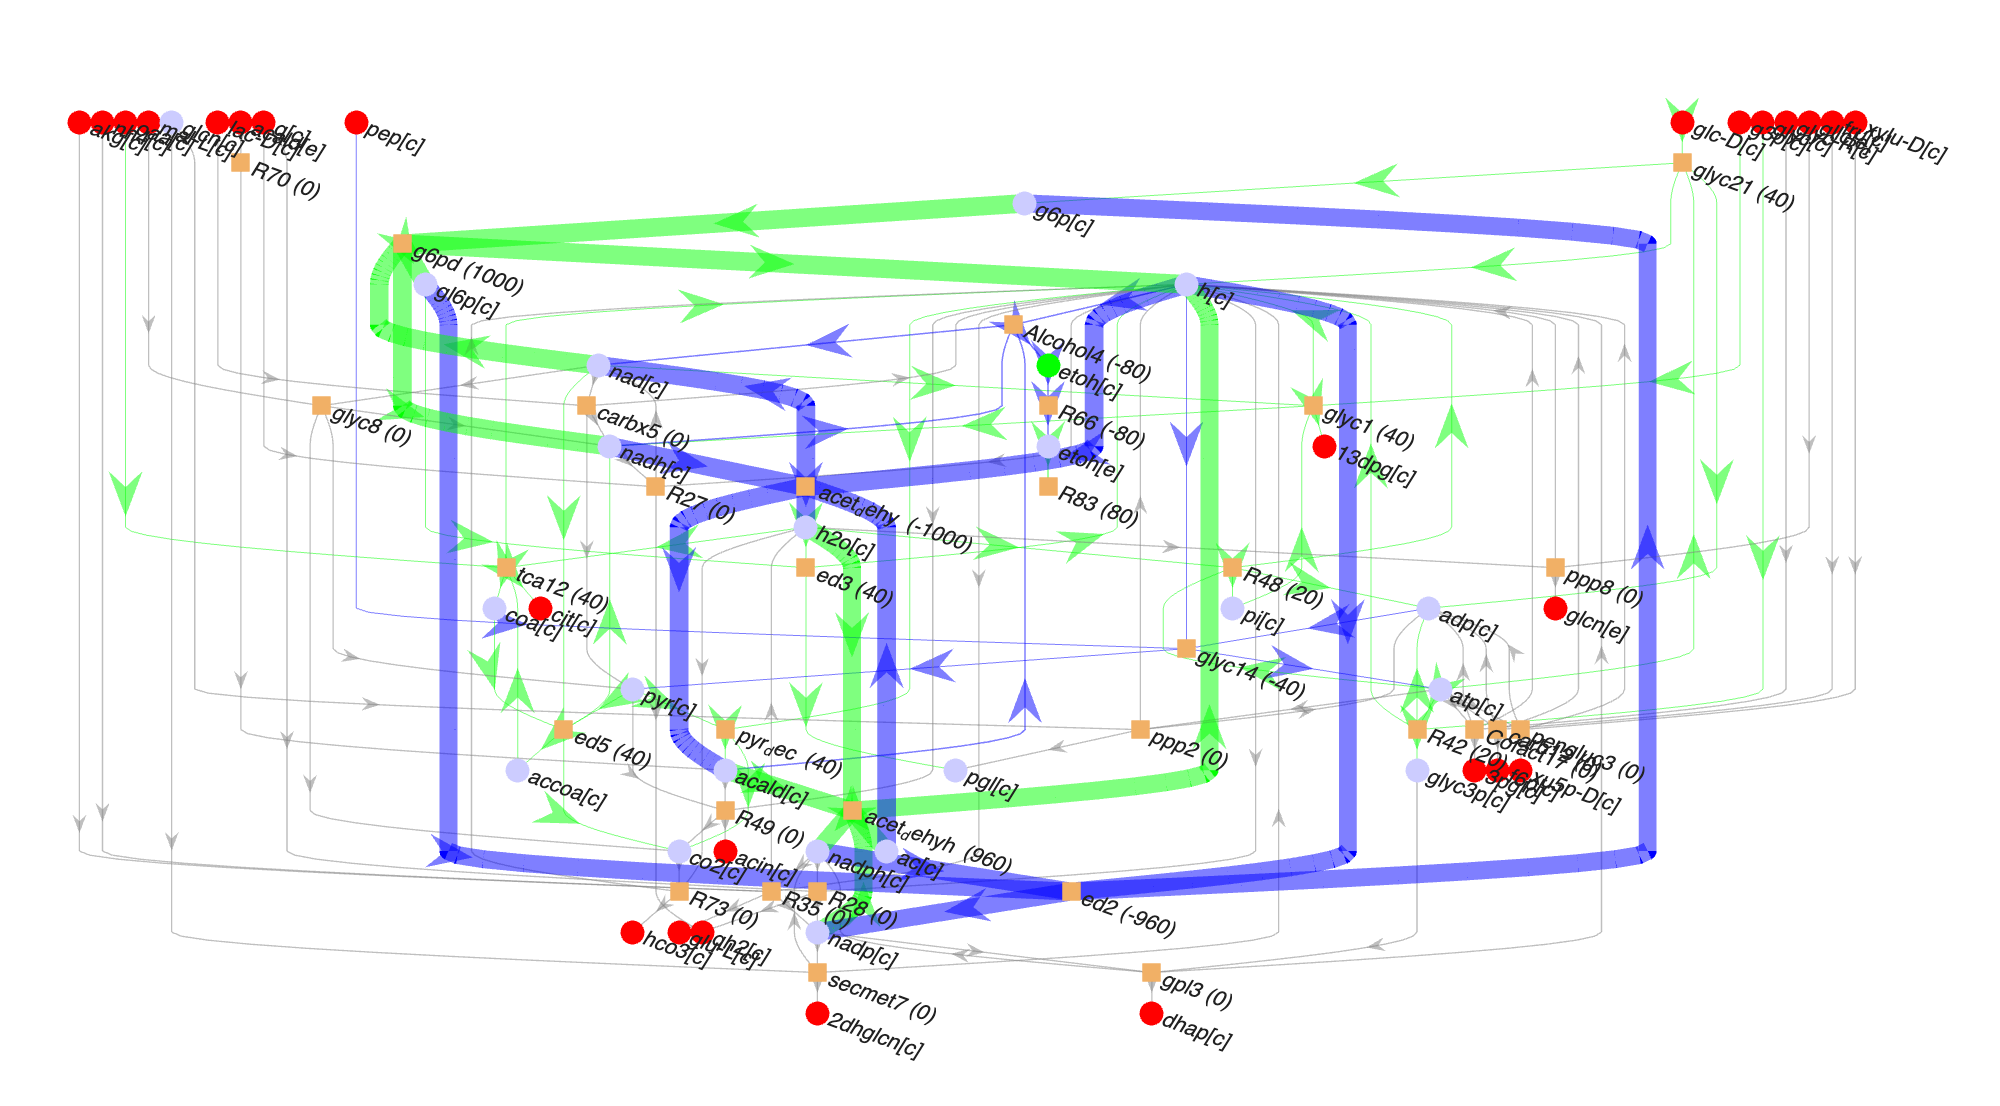

**iii.  argument *****drawMap***

It is a *logical* type variable that can take value of *'true'* or *'false*' (default is *'false'*) indicating whether to visualize the COBRA model or not*. *The main idea of this argument is to ensure possibility to save time by not visualizing a large COBRA model and get a result  faster.

Start_time = '2026_3_10_19_5_59.7641'

Alcohol4	nad[c] + etoh[c] 	<=>	h[c] + nadh[c] + acald[c] 
R66	etoh[e] 	<=>	etoh[c] 
Metabolite nodes - light blue: Reaction nodes - Orange


h =   GraphPlot with properties:

     NodeColor: [8×3 double]
    MarkerSize: 8
        Marker: {'o'  'o'  'o'  'o'  'o'  'o'  'square'  'square'}
     EdgeColor: [7×3 double]
     LineWidth: [0.5600 0.5600 0.5600 0.5600 0.5600 0.5600 0.5600]
     LineStyle: '-'
     NodeLabel: {'h[c]'  'nad[c]'  'nadh[c]'  'acald[c]'  'etoh[c]'  'etoh[e]'  'Alcohol4 (-80)'  'R66 (-80)'}
     EdgeLabel: {}
         XData: [1 1.5000 2 3 2.5000 2.5000 2 2.5000]
         YData: [5 3 5 5 3 1 4 2]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


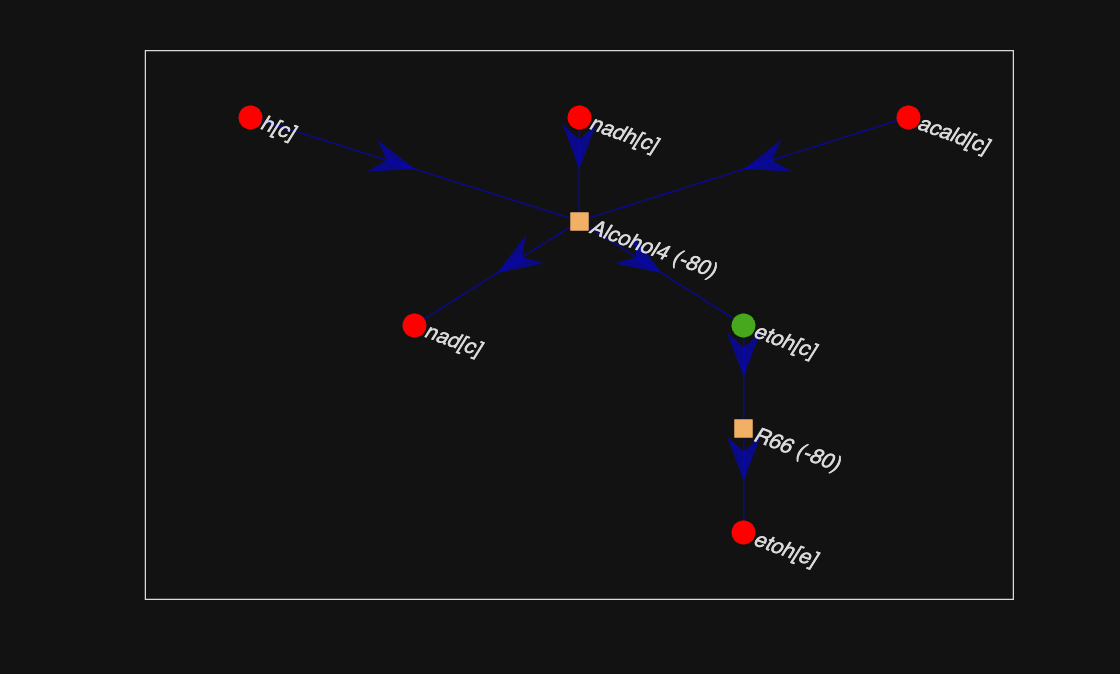

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'etoh[c]'}, 'true', ... 
    1, 'both', {''}, FBAsolution.x);

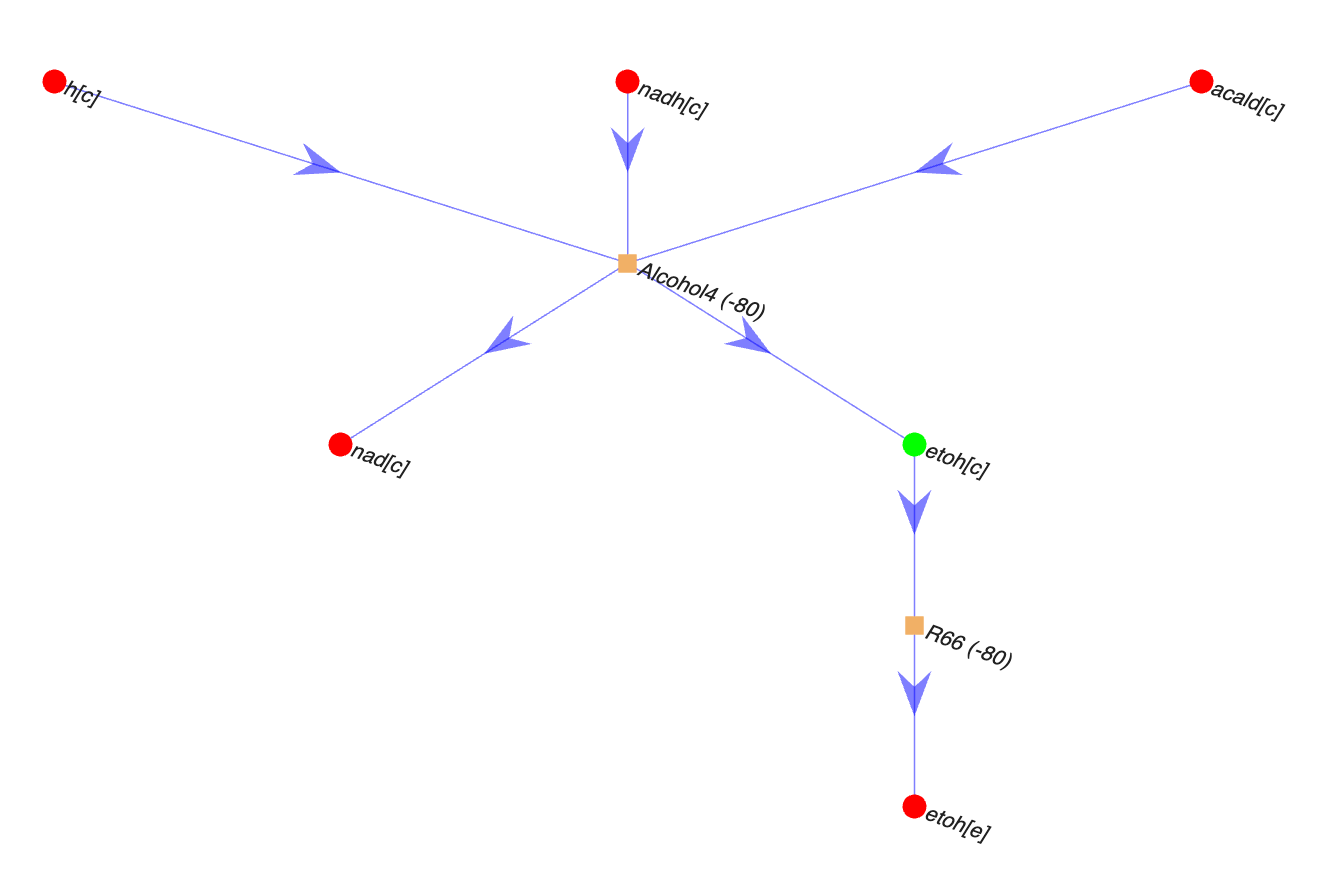

**iv.  argument *****radius***

It is a *double* type variable that can take a value of natural numbers (1,2,3…n).

Start_time = '2026_3_10_19_6_4.3407'

Alcohol4	nad[c] + etoh[c] 	<=>	h[c] + nadh[c] + acald[c] 
Metabolite nodes - light blue: Reaction nodes - Orange


h =   GraphPlot with properties:

     NodeColor: [5×3 double]
    MarkerSize: 8
        Marker: {'o'  'o'  'o'  'o'  'square'}
     EdgeColor: [4×3 double]
     LineWidth: [0.5600 0.5600 0.5600 0.5600]
     LineStyle: '-'
     NodeLabel: {'h[c]'  'nadh[c]'  'acald[c]'  'etoh[c]'  'Alcohol4 (-80)'}
     EdgeLabel: {}
         XData: [1 2 3 2 2]
         YData: [3 3 3 1 2]
         ZData: [0 0 0 0 0]

  Show all properties


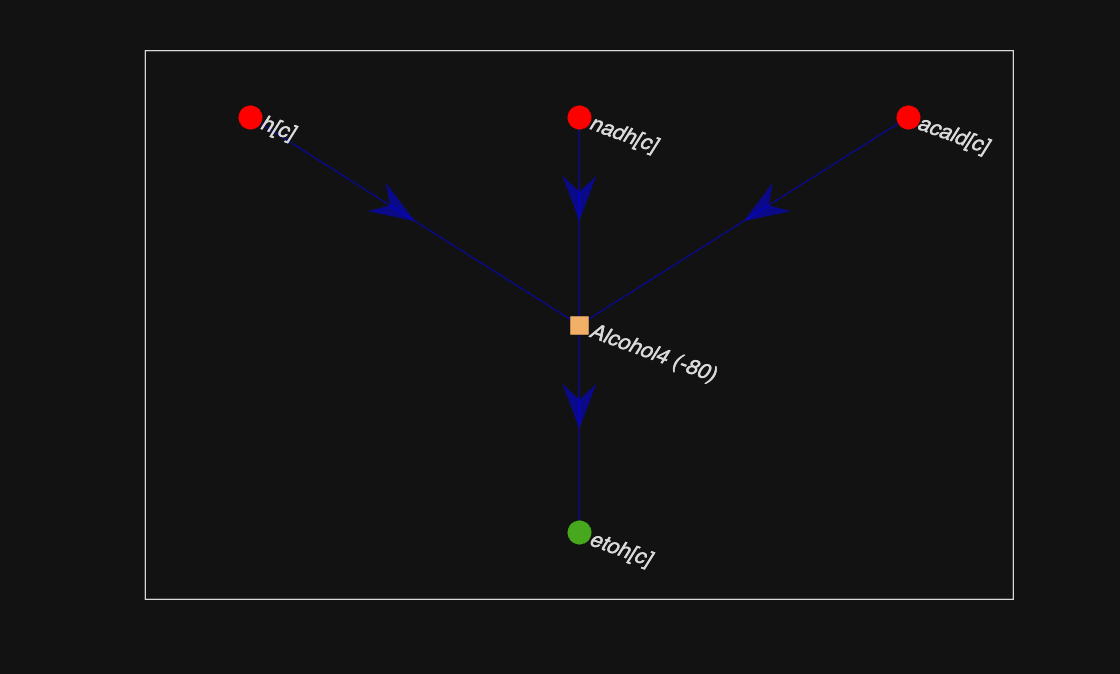

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'etoh[c]'}, 'true', 1,...
    'sub', {''}, FBAsolution.x);

The argument *radius *indicates the depth of an analysis of the initial metabolite (the argument *metAbbr*) and it is tightly connected to the optional argument *direction. *For example, if user is interested in the substrates of *ethanol*, the user can analyse substrates step by step starting from the first reactions where the argument *radius* is equal to 1 and moving to the next reactions by increasing the value of the argument *radius* (see Fig. 13 and Fig. 14).

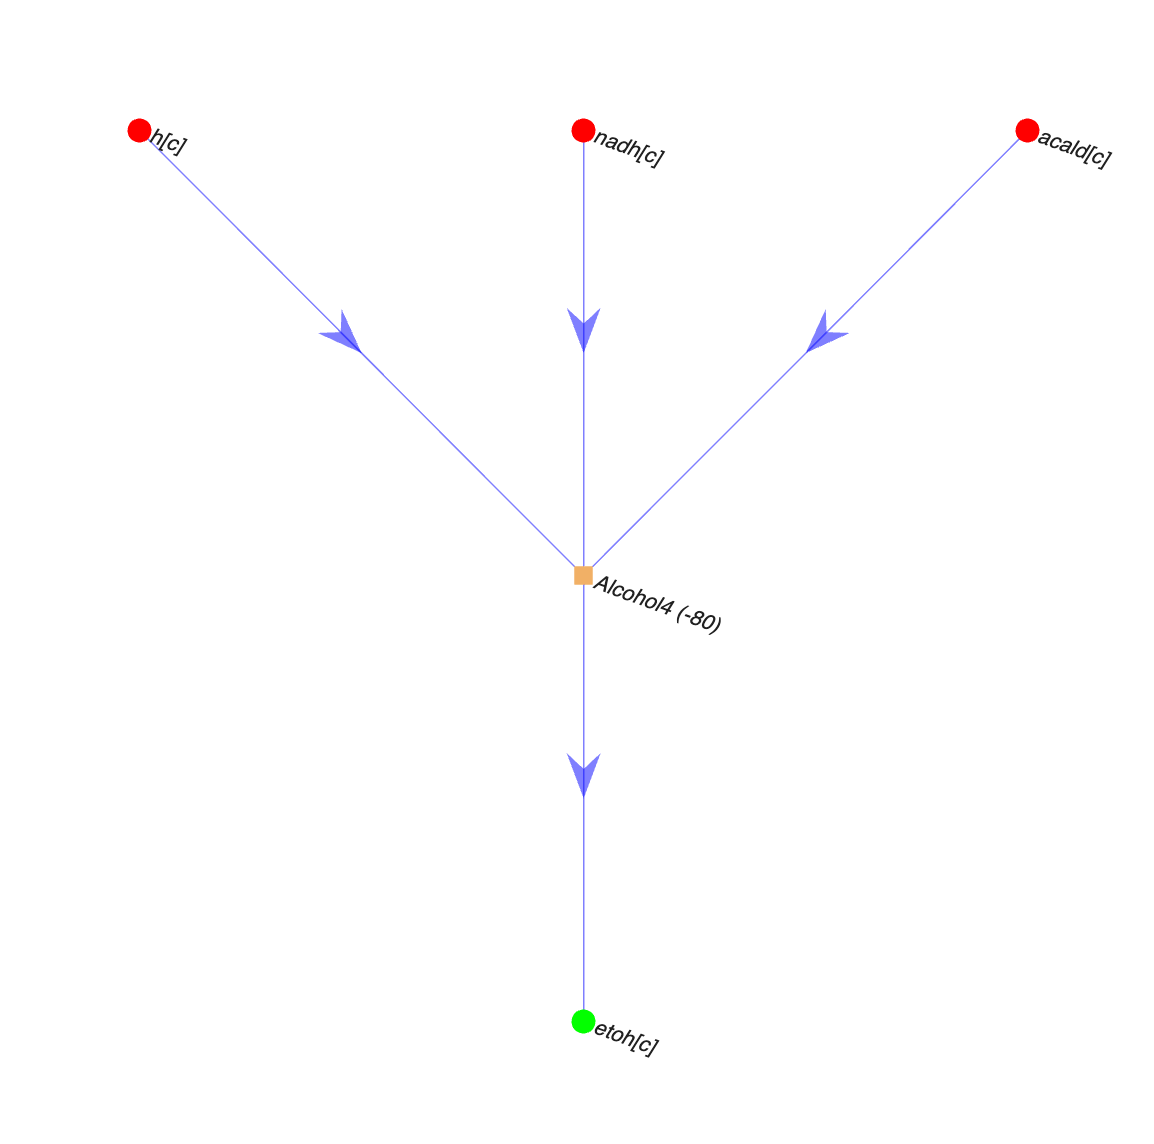

**Fig. 13.** Example where the argument *radius *= 1 (distance = one reaction from initial metabolite *etoh[c]*). In the reaction *Alchocol4* the metabolites *h[c]*, *nadh[c]*, and *acald[c]* are consumed and the metabolite *etoh[c] *is produced. The flux rate is -80 mmol*g-1*h-1that indicates that reaction is going backwards.

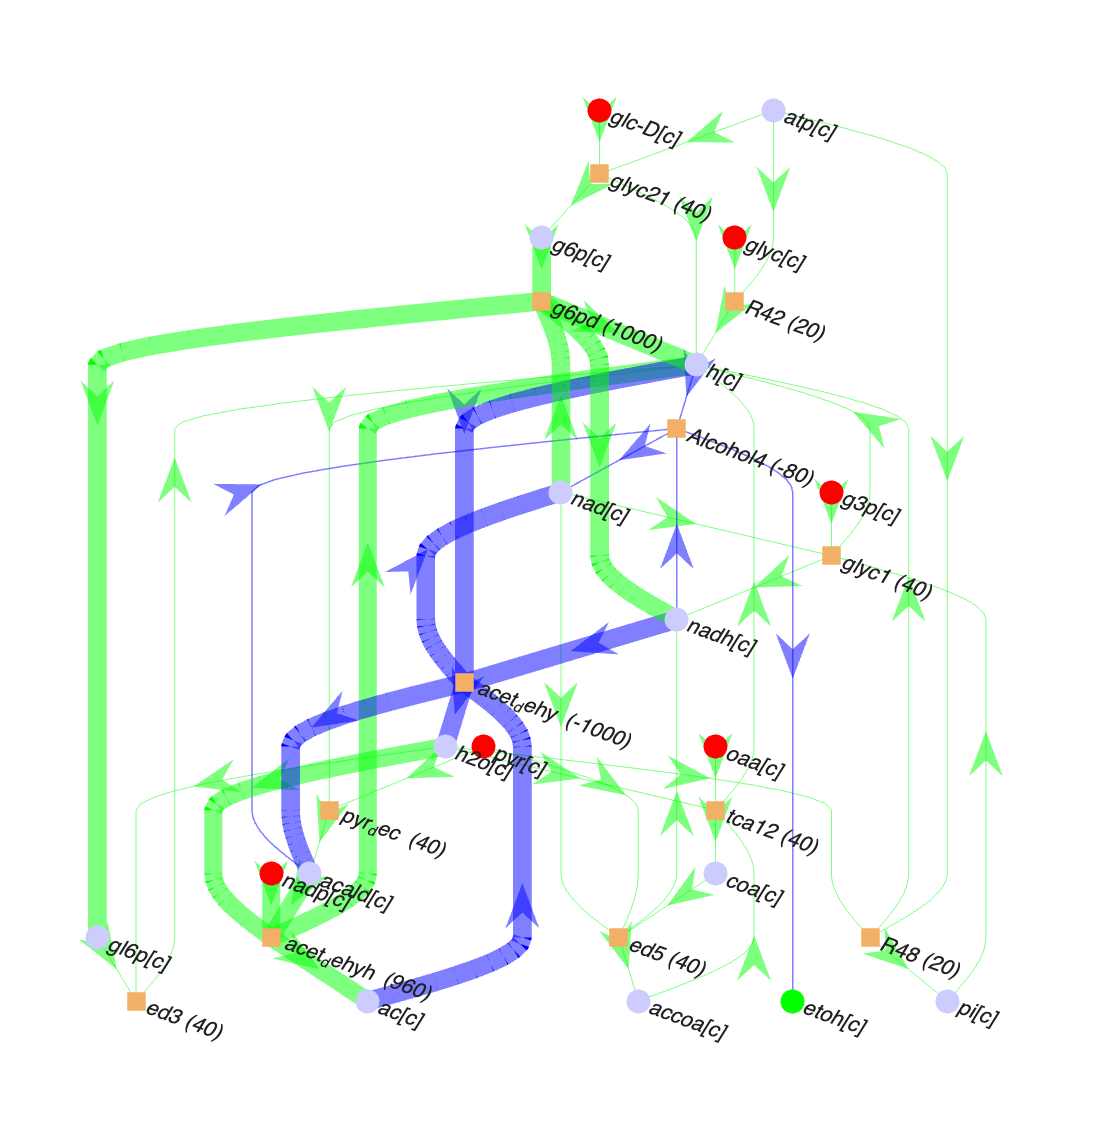

**Fig. 14.** Example where the argument *radius* = 2 (distance = two reactions from initial metabolite *etoh[c]*). The metabolites *glyc-R[c]*, *glc-D[c]*, *h2o[c]*, *pyr[c]*, *g3p[c]*, and *pi[c]* are consumed and the metabolite *etoh[c] *is produced.

The algorithm of the command *draw_by_met* interconnects all involved metabolites according to the stoichiometric matrix of a COBRA model. The important point to understand correctly is imbalance of the rates of fluxes in case of partial network. The algorithm of the command *draw_by_met* shows the rates of fluxes in the brackets in the rectangles according to steady state, but in case of visualization of partial network not all rectangles are seen which leads to imbalance for some metabolites. For example, in the Fig. 14 the metabolite *h[c]* is produced in 5 reactions (*Cofact17*, *glyc21*, *ed3*, *g6pd*, and *glyc1*) with total 5*40=200 mmol*g-1*h-1 but it is consumed in 2 reactions (*pyr_dec*and *Alchocol4*) with only 2*80 = 160 mmol*g-1*h-1.

**v. argument *****direction***

It is a *string *type variable that can take value of *'****struc****'*, *'****sub****'*, *'****prod****'* or *'****both****'* (default is *'struc'*) indicating a direction for the algorithm of the command *draw_by_met. *In case of *'struc'* (structure) the algorithm visualizes all metabolites connected to the specified reactions in the argument *rxns*. The key feature of this function is visualization of all specified reactions not taking in account a steady state fluxes in that way representing the structure of the COBRA model. In case of *'sub'* (substrates) the algorithm visualizes only those metabolites which are substrates for the specified reactions in the argument *rxns*. This time the algorithm is using a stoichiometric matrix and the steady state fluxes to determine direction of each reaction. The algorithm is using an assumption that only those fluxes which rates are smaller than -10-9 mmol*g-1*h-1or greater than +10-9 mmol*g-1*h-1 are non-zero fluxes. In case of *'prod'* (products) the algorithm visualizes only those metabolites which are products for the specified reactions in the argument *rxns* but in case of *'both' *the algorithm visualizes both – substrates and products - for the specified reactions in the argument *rxns*. For both cases the algorithm is using the same rules regarding to calculation of the directions for each reaction as for case of *'sub'*.

**vi. ****optional**** argument *****excludeMets***

This is the only optional argument in the latest version of Paint4Net, and represents a list of metabolites (default is empty) that will be excluded from the visualization map of the COBRA model in form of the abbreviations of the metabolites separated by a comma. 

**vii. argument *****flux***

It is a *double* type Nx1 size vector of fluxes of reactions where N is number of reactions (default is vector of x). This vector is calculated during the optimization of the objective function and can be accessed through the result of the optimization command by *FBAsolution.x.*

## *Output of the command draw_by_met *

The command *draw_by_met *has three output vectors in the result: *involvedRxns*,* involvedMets*, and *deadEnds*.

**i. vector *****involvedRxns***

It is a *cell *type vector that contains a list of the involved reactions according to the set of input arguments (see **Fig. 15**).

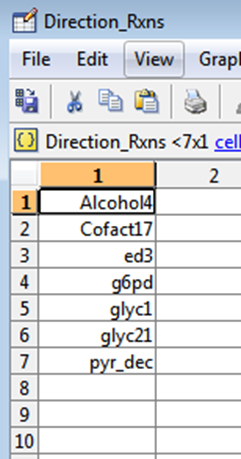

**Fig. 15. **An example of the list of the involved reactions.

**ii. vector *****involvedMets***

It is a *cell *type vector that contains a list of the involved metabolites in the specified reactions (see Fig. 10).

**iii. vector *****deadEnds***

It is also a *cell *type vector but it contains a list of the dead end metabolites in the specified reactions (see Fig. 11).

## TROUBLESHOOTING

**Problem: **output vectors ar valid, but visuaization layout is not generated.

**Possible reason: **the input argument *drawMap *is not provided properly.

**Solution: **It is a *logical* type variable that can take value of *'true'* or *'false*' (default is *'false'*) indicating whether to visualize the COBRA model or not. Please pay attention to single quotes around the argument.

## TIMING

Timing is given as Start_time, End_time and Total_time for every Paint4Net function call. It may varie based on equipment computing power.

## Acknowledgments

Authors are thankful to Ines Thiele who inspired to make a simple visualization software for COBRA models. 

This work is funded by a project of European Structural Fund Nr. 2009/0207/1DP/1.1.1.2.0/09/APIA/VIAA/128 “Latvian Interdisciplinary Interuniversity Scientific Group of Systems Biology” www.sysbio.lv.

## REFERENCES

Aurich, M.K., Thiele, I., 2012. Contextualization Procedure and Modeling of Monocyte Specific TLR Signaling. PLoS One 7, e49978. doi:10.1371/journal.pone.0049978

Contador, C.A., Rodr?guez, V., Andrews, B.A., Asenjo, J.A., 2015. Genome-scale reconstruction of Salinispora tropica CNB-440 metabolism to study strain-specific adaptation. Antonie Van Leeuwenhoek 108, 1075–1090. doi:10.1007/s10482-015-0561-9

Demidenko, A., Akberdin, I.R., Allemann, M., Allen, E.E., Kalyuzhnaya, M.G., 2017. Fatty Acid Biosynthesis Pathways in Methylomicrobium buryatense 5G(B1). Front. Microbiol. 7. doi:10.3389/fmicb.2016.02167

Koussa, J., Chaiboonchoe, A., Salehi-Ashtiani, K., 2014. Computational Approaches for Microalgal Biofuel Optimization: A Review. Biomed Res. Int. 2014, 1–12. doi:10.1155/2014/649453

Mao, L., Verwoerd, W.S., 2014. ORCA: a COBRA toolbox extension for model-driven discovery and analysis. Bioinformatics 30, 584–585. doi:10.1093/bioinformatics/btt723

Meitalovs, J., Stalidzans, E., 2013. Analysis of synthetic metabolic pathways solution space, in: 2013 International Conference on System Science and Engineering (ICSSE). Ieee, pp. 183–187. doi:10.1109/ICSSE.2013.6614656

Palsson, B.O., 2006. Systems Biology: Properties of Reconstructed Networks. Cambridge University Press, New York.

Pentjuss, A., Odzina, I., Kostromins, A., Fell, D.A., Stalidzans, E., Kalnenieks, U., 2013. Biotechnological potential of respiring Zymomonas mobilis: a stoichiometric analysis of its central metabolism. J. Biotechnol. 165, 1–10. doi:10.1016/j.jbiotec.2013.02.014

Pentjuss, A., Stalidzans, E., Liepins, J., Kokina, A., Martynova, J., Zikmanis, P., Mozga, I., Scherbaka, R., Hartman, H., Poolman, M.G., Fell, D.A., Vigants, A., 2017. Model-based biotechnological potential analysis of Kluyveromyces marxianus central metabolism. J. Ind. Microbiol. Biotechnol. doi:10.1007/s10295-017-1946-8

Richards, M.A., Lie, T.J., Zhang, J., Ragsdale, S.W., Leigh, J.A., Price, N.D., 2016. Exploring Hydrogenotrophic Methanogenesis: a Genome Scale Metabolic Reconstruction of Methanococcus maripaludis. J. Bacteriol. 198, 3379–3390. doi:10.1128/JB.00571-16

Rove, Z., Mednis, M., Odzina, I., 2012. Biochemical networks comparison tool, in: 5th International Scientific Conference on Applied Information and Communication Technologies. Jelgava, Latvia., pp. 306–311.

Rubina, T., Stalidzans, E., 2013. BINESA — A software tool for evolution modelling of biochemical networks’ structure, in: 2013 IEEE 14th International Symposium on Computational Intelligence and Informatics (CINTI). IEEE, pp. 345–350. doi:10.1109/CINTI.2013.6705218

Thiele, I., Palsson, B.Ø., 2010. A protocol for generating a high-quality genome-scale metabolic reconstruction. Nat. Protoc. 5, 93–121. doi:10.1038/nprot.2009.203